% Options for data alignment
ops.cameraTriggerChan = 11;
ops.treadmillChan = 14;
ops.overwrite = false;
ops1.method = 'baseline';

load('D:\Dropbox (EinsteinMed)\Jacob\data and docs\MATLAB\live_scripts\SST_nNOS_sleep_imaging\cellIDs.mat')
load('D:\Dropbox (EinsteinMed)\Jacob\data and docs\MATLAB\live_scripts\SST_nNOS_sleep_imaging\cellIDs_sleep.mat')

% Animal4627(3:4) = [];

## Animal 4612

Animal 4612 Day 1

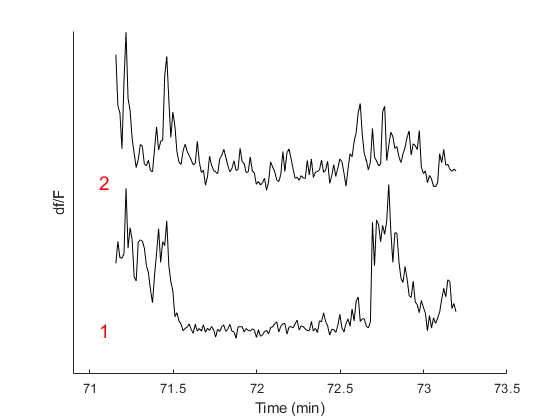

basepath = 'G:\sleep_wake_recordings\4612\JR_21_12_02_confon_GCaMP_4612\JR_21_12_02_confon_GCaMP_4612_211202_135703';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4612\JR_21_12_02_confon_GCaMP_4612\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366,ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
lfpReref.timestamps = lfpReref.timestamps - imgStruct.firstScopeFrameTime;

Animal4612(1).ID = 4612;
Animal4612(1).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4612(1).ID, Animal4612(1).cellIDs);

Loading cell type data extracted 28-Apr-2026 07:59:32


output = struct with fields:
    HighActivitySpec: [1×100 double]
     LowActivitySpec: [1×100 double]


Animal 4612 Day 2

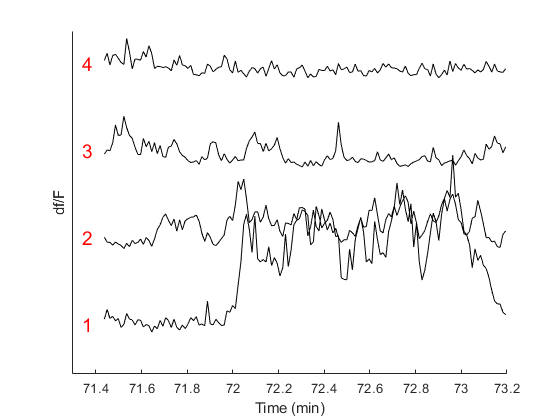

basepath = 'G:\sleep_wake_recordings\4612\JR_21_12_07_confon_GCaMP_4612_2\JR_21_12_07_confon_GCaMP_4612_211207_140953';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4612\JR_21_12_07_confon_GCaMP_4612_2\field1_001';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


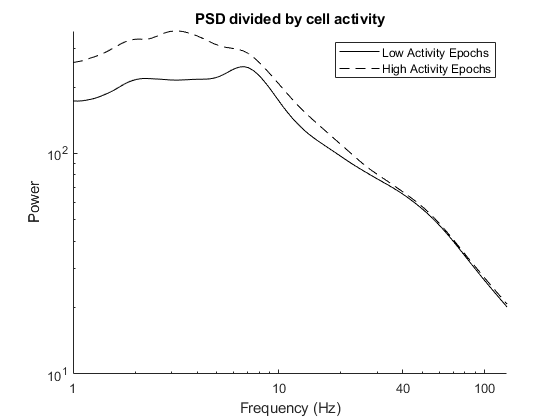

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


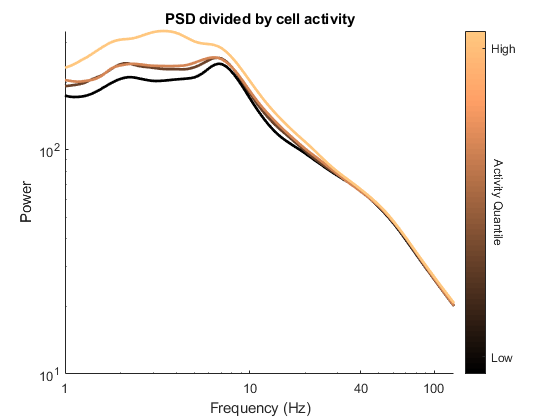

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal4612(2).ID = 4612;
Animal4612(2).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4612(2).ID, Animal4612(2).cellIDs);

Animal 4612 Day 3

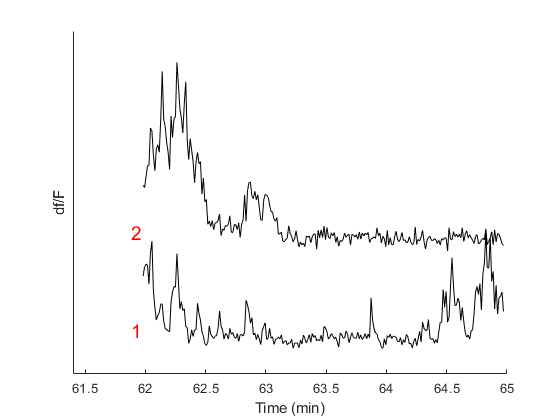

basepath = 'G:\sleep_wake_recordings\4612\JR_21_12_10_confon_GCaMP_4612\JR_21_12_10_confon_GCaMP_4612_211210_130217';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4612\JR_21_12_10_confon_GCaMP_4612\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


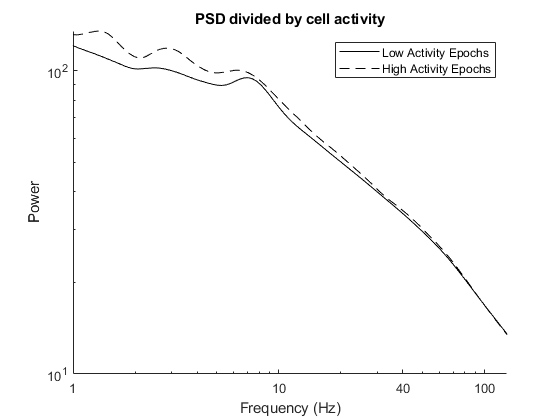

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


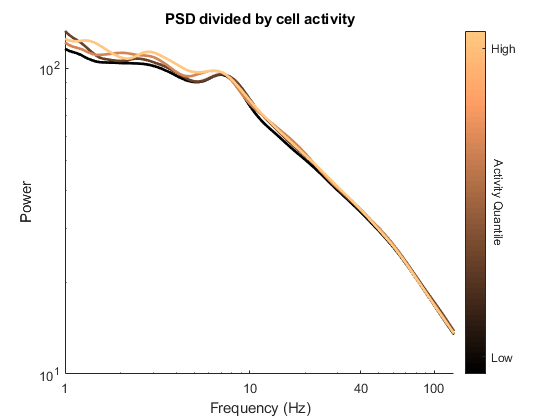

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4612(3).ID = 4612;
Animal4612(3).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4612(3).ID, Animal4612(3).cellIDs);

Animal 4612 Day 4

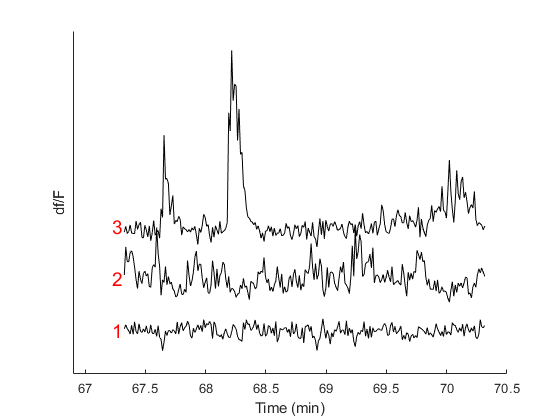

basepath = 'G:\sleep_wake_recordings\4612\JR_21_12_14_confon_GCaMP_4612\JR_21_12_14_confon_GCaMP_4612_211214_145056';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4612\JR_21_12_14_confon_GCaMP_4612\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


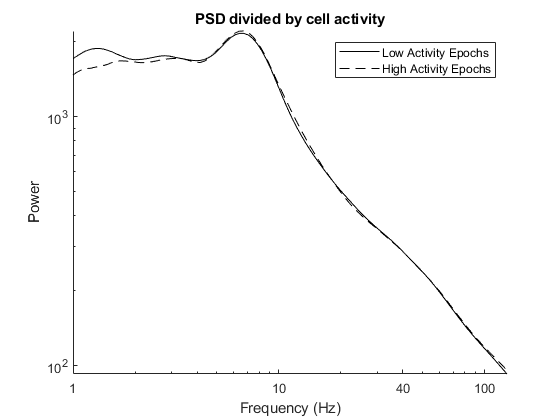

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


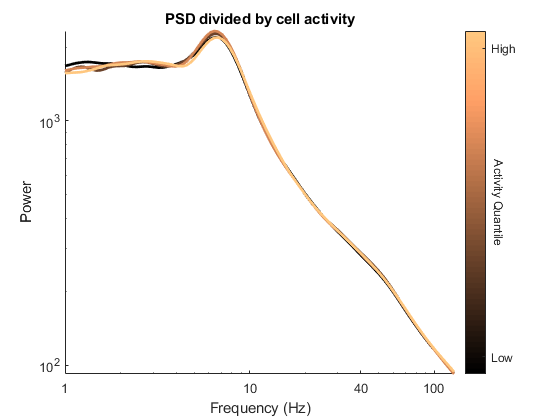

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4612(4).ID = 4612;
Animal4612(4).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4612(4).ID, Animal4612(4).cellIDs);

Animal 4612 Day 5

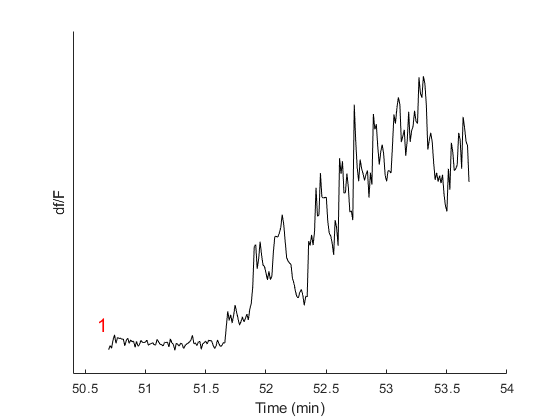

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_03_09_confon_GCaMP_4612\JR_22_03_09_confon_GCaMP_4612_220309_171624';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_03_09_confon_GCaMP_4612\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


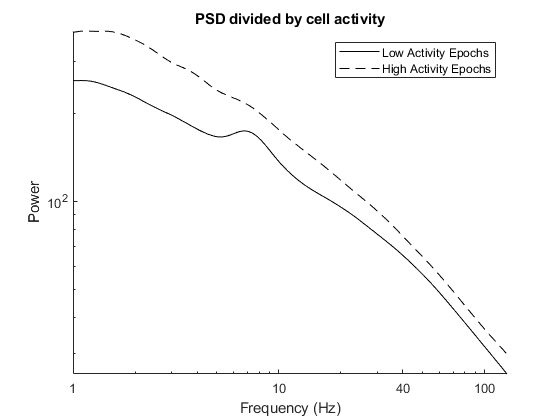

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


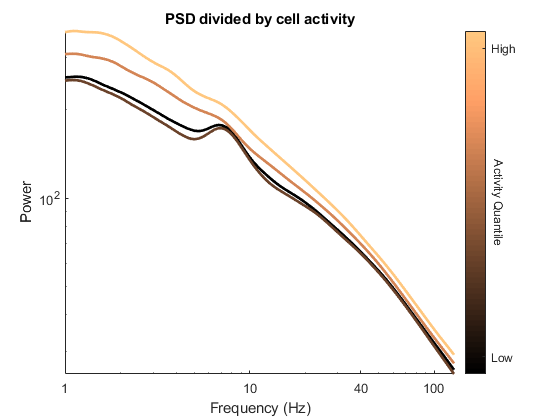

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4612(5).ID = 4612;
Animal4612(5).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4612(5).ID, Animal4612_sleep(1).cellIDs);

Animal4612(5).cellIDs = Animal4612_sleep(1).cellIDs;

Animal 4612 Day 6

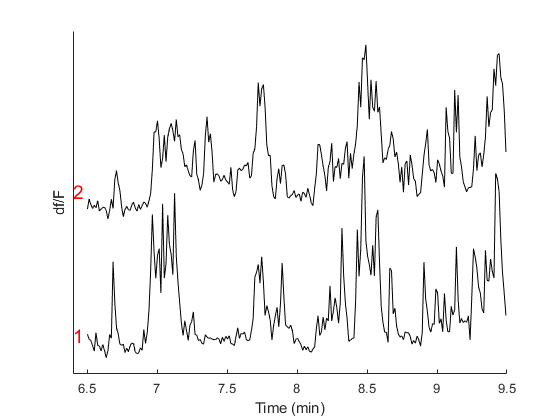

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_05_11_confon_GCaMP_4612\JR_22_05_11_confon_GCaMP_4612_220511_180252';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_05_11_confon_GCaMP_4612\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


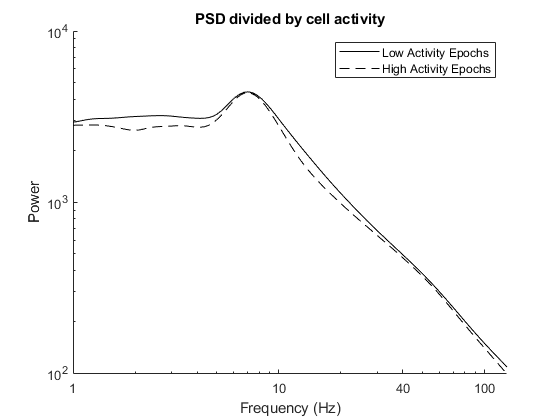

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


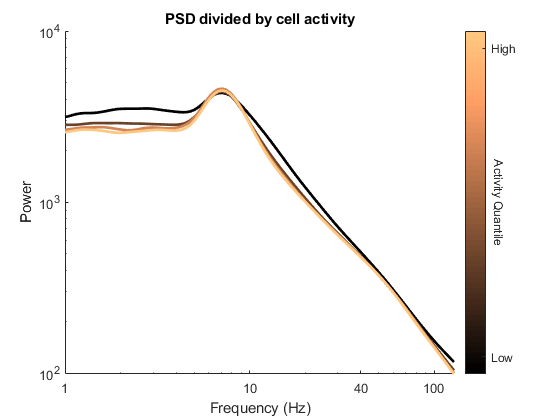

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4612(6).ID = 4612;
Animal4612(6).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4612(6).ID, Animal4612_sleep(2).cellIDs);

Animal4612(6).cellIDs = Animal4612_sleep(2).cellIDs;

## Animal 4621

Animal 4621 Day 1

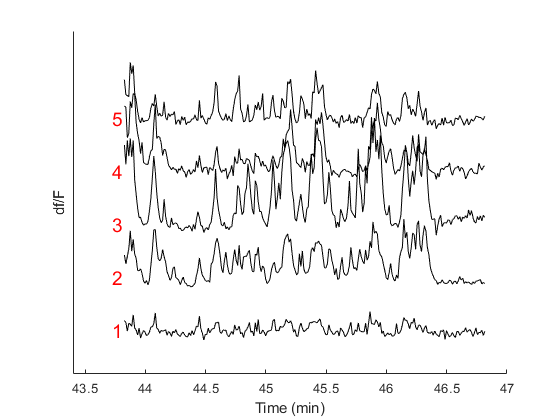

basepath = 'G:\sleep_wake_recordings\4621\JR_21_12_03_confon_GCaMP_4621\JR_21_12_03_confon_GCaMP_4621_211203_133720';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4621\JR_21_12_03_confon_GCaMP_4621\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


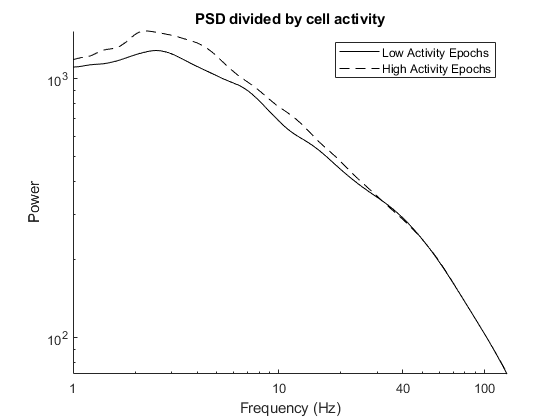

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


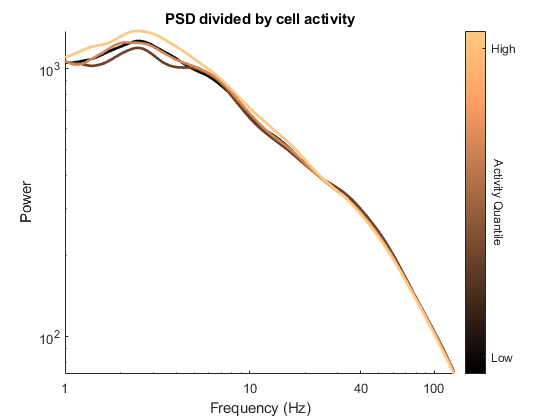

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal4621(1).ID = 4621;

% Analyze session
Animal4621(1).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4621(1).ID, Animal4621(1).cellIDs);

Animal 4621 Day 2

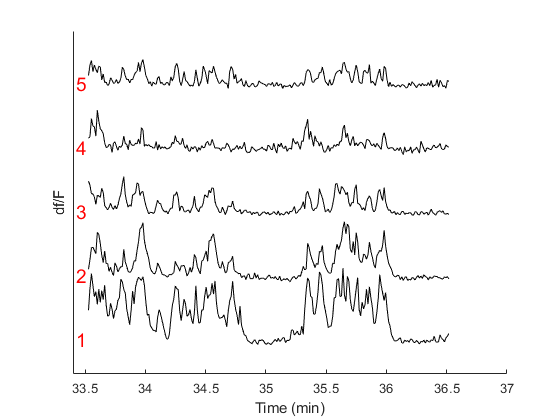

basepath = 'G:\sleep_wake_recordings\4621\JR_21_12_07_confon_GCaMP_4621\JR_21_12_07_confon_GCaMP_4612_211207_161105';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4621\JR_21_12_07_confon_GCaMP_4621\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


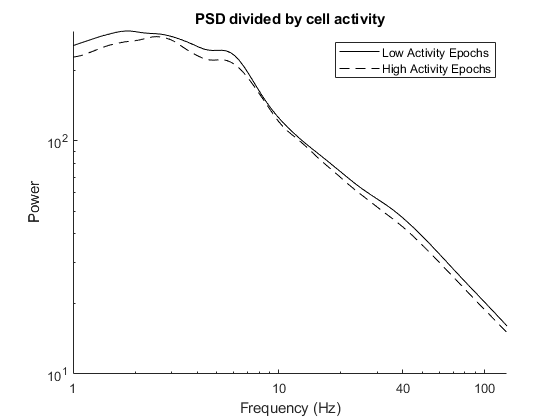

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


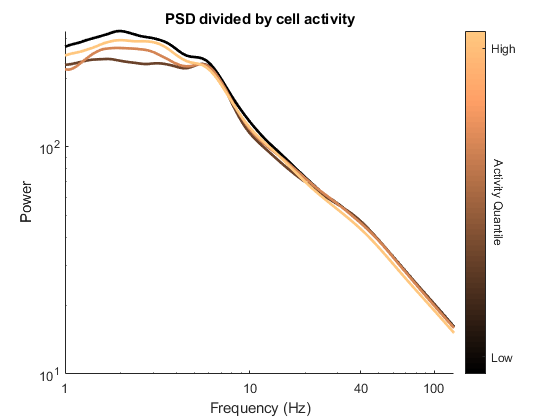

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4621(2).ID = 4621;
Animal4621(2).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4621(2).ID, Animal4621(2).cellIDs);

Animal 4621 Day 3

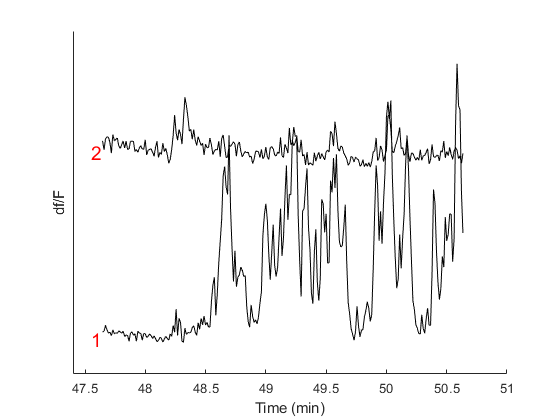

basepath = 'G:\sleep_wake_recordings\4621\JR_21_12_10_confon_GCaMP_4621\JR_21_12_10_confon_GCaMP_4621_211210_152259';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4621\JR_21_12_10_confon_GCaMP_4621\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


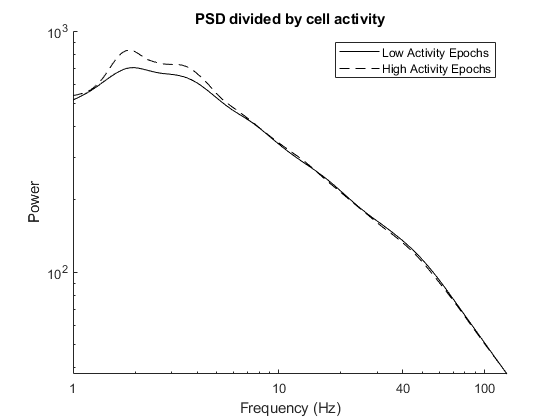

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


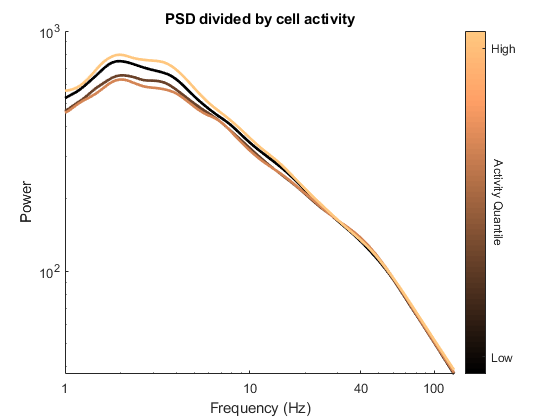

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4621(3).ID = 4621;
Animal4621(3).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4621(3).ID, Animal4621(3).cellIDs);

Animal 4621 Day 4

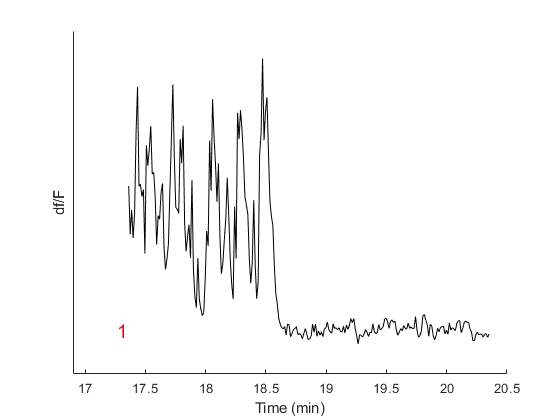

basepath = 'G:\sleep_wake_recordings\4621\JR_21_12_15_confon_GCaMP_4621\JR_21_12_15_confon_GCaMP_4621_211215_095340';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4621\JR_21_12_15_confon_GCaMP_4621\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


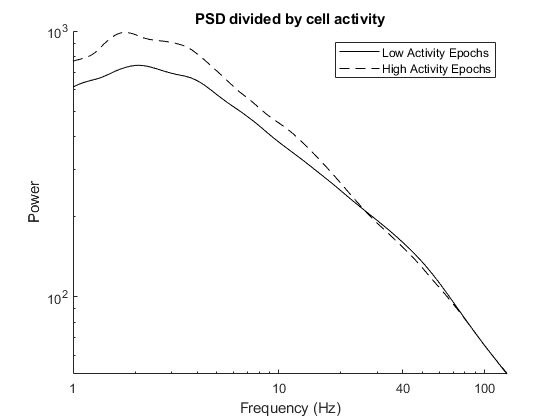

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


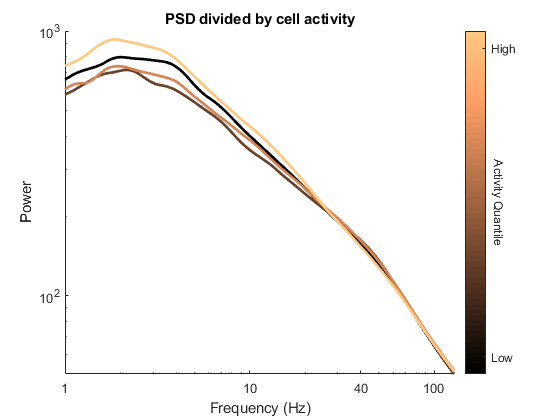

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4621(4).ID = 4621;
Animal4621(4).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4621(4).ID, Animal4621(4).cellIDs);

## Animal 4622

Single recording not of sufficient quality

## Animal 4627

Animal 4627 Day 1

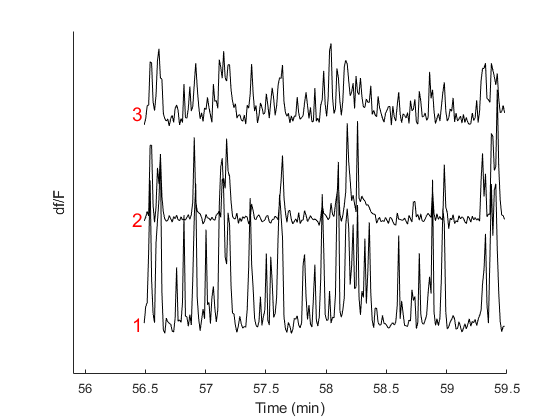

basepath = 'G:\sleep_wake_recordings\4627\JR_21_12_02_confon_GCaMP_4627\JR_21_12_02_confon_GCaMP_4627_211202_102220';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4627\JR_21_12_02_confon_GCaMP_4627\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


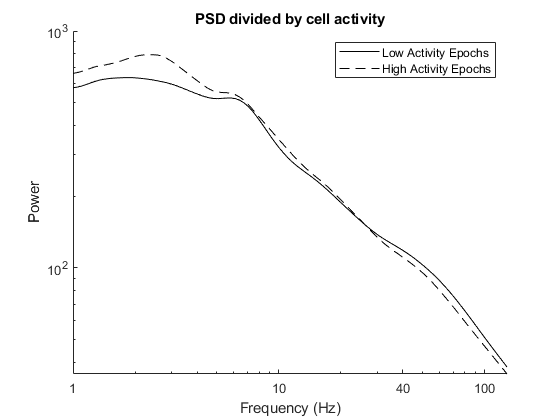

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


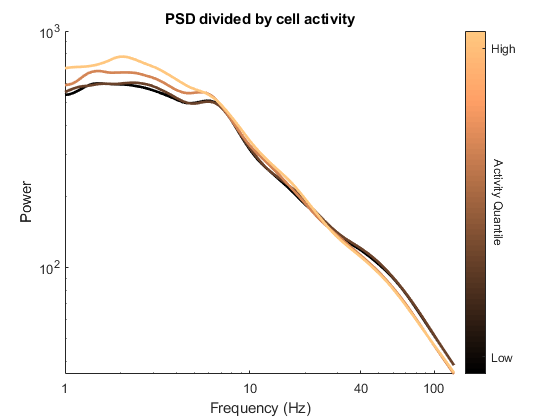

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal4627(1).ID = 4627;

% Analyze session
Animal4627(1).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4627(1).ID, Animal4627(1).cellIDs);

Animal 4627 Day 2

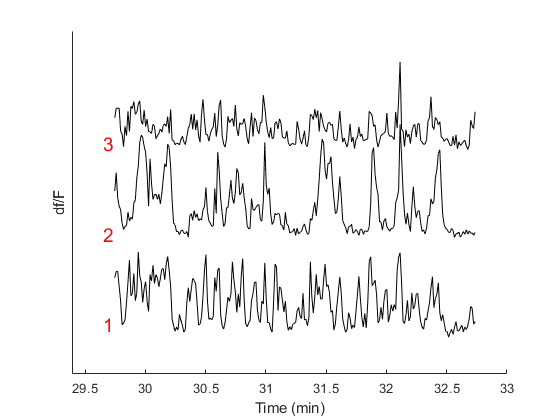

basepath = 'G:\sleep_wake_recordings\4627\JR_21_12_06_confon_GCaMP_4627\JR_21_12_06_confon_GCaMP_4627_211206_144336';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4627\JR_21_12_06_confon_GCaMP_4627\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


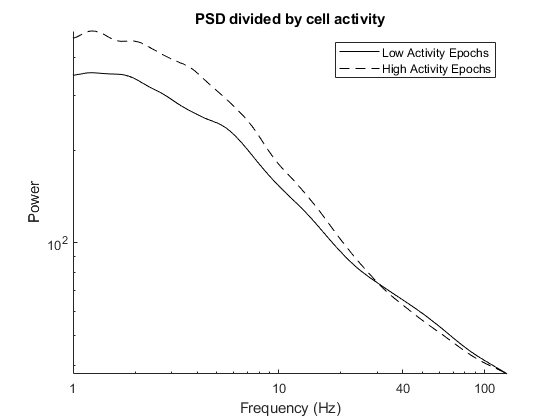

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


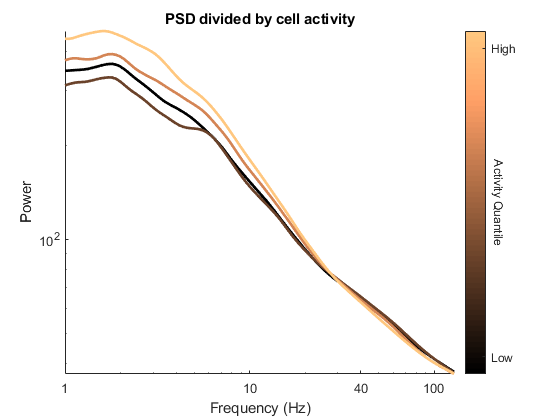

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4627(2).ID = 4627;
Animal4627(2).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4627(2).ID, Animal4627(2).cellIDs);

Animal 4627 Day 3

This session had an issue with the camera data

Animal 4627 Day 4

This session has an issue with the z plane changing

Animal 4627 Day 5

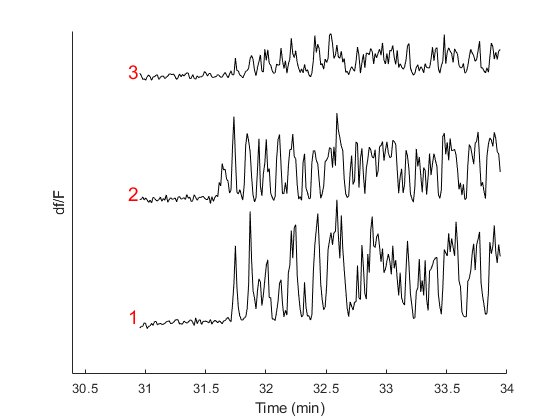

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_05_09_confon_GCaMP_4627\JR_22_05_09_confon_GCaMP_4627_220509_154655';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_05_09_confon_GCaMP_4627\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


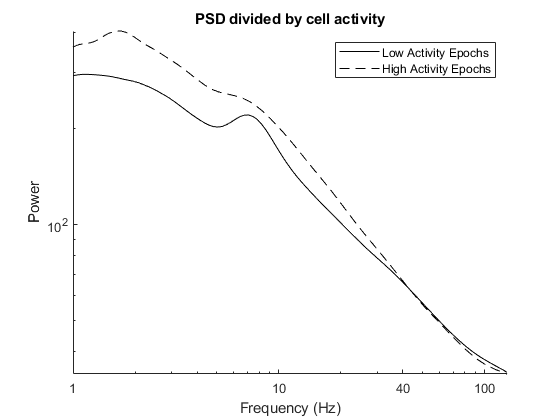

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


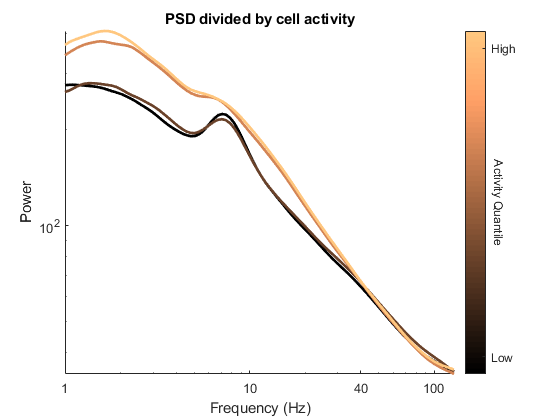

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4627(3).ID = 4627;
Animal4627(3).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4627(3).ID, Animal4627_sleep(1).cellIDs);

Animal4627(3).cellIDs = Animal4627_sleep(1).cellIDs;

Animal 4627 Day 6

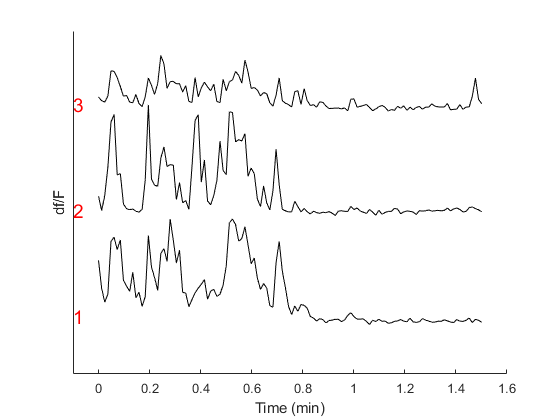

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_07_12_confon_GCaMP_4627\JR_22_07_12_confon_GCaMP_4627_220712_145339';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_07_12_confon_GCaMP_4627\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


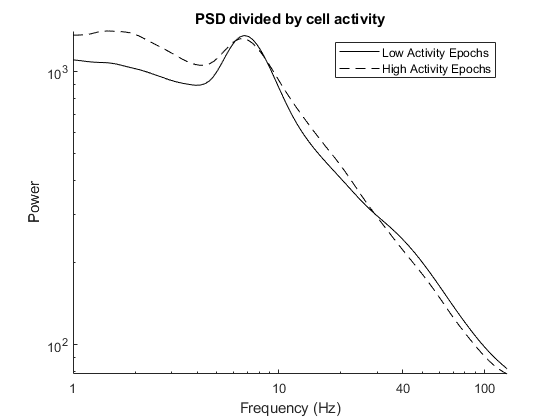

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


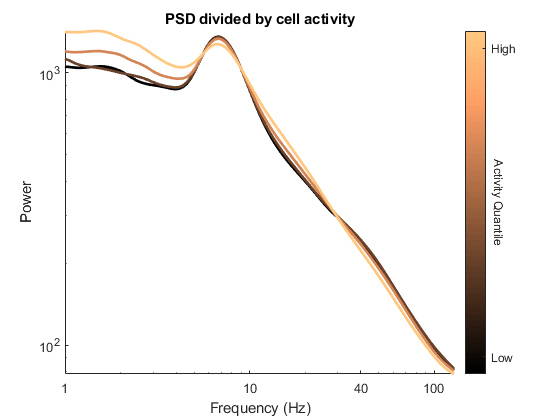

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4627(4).ID = 4627;
Animal4627(4).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4627(4).ID, Animal4627_sleep(2).cellIDs);

Animal4627(4).cellIDs = Animal4627_sleep(2).cellIDs;

## Animal 4632

Animal 4632 Day 1

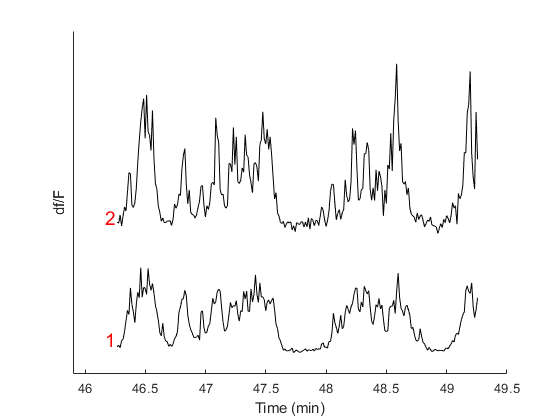

basepath = 'G:\sleep_wake_recordings\4632\JR_21_12_06_confon_GCaMP_4632\JR_21_12_06_confon_GCaMP_4632_211206_121708';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4632\JR_21_12_06_confon_GCaMP_4632\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


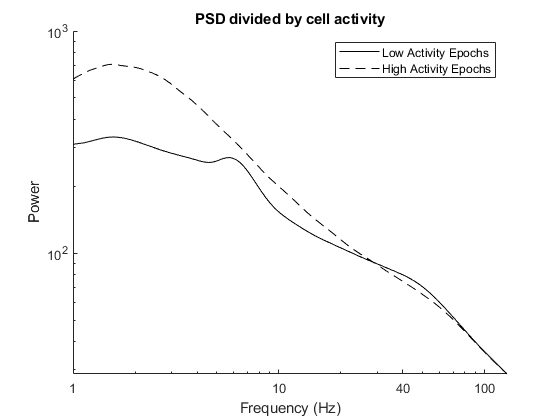

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


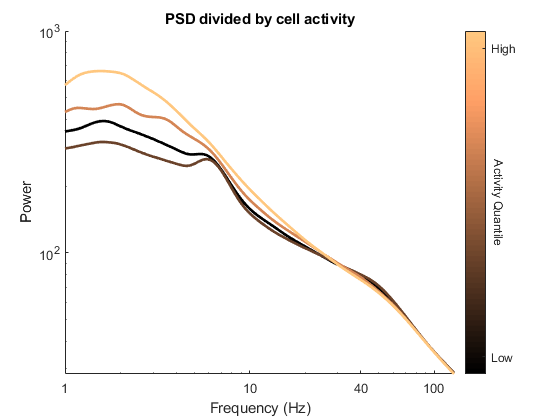

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal4632(1).ID = 4632;

% Analyze session
Animal4632(1).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4632(1).ID, Animal4632(1).cellIDs);

Animal 4632 Day 2

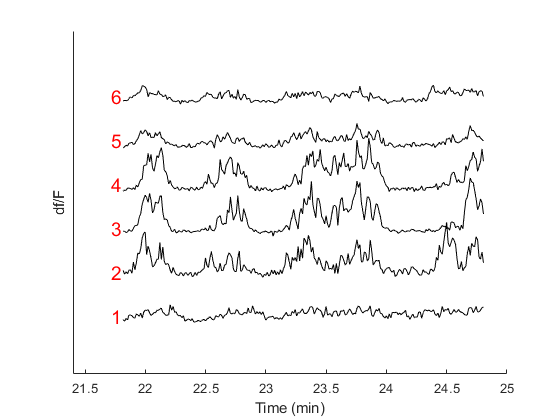

basepath = 'G:\sleep_wake_recordings\4632\JR_21_12_08_confon_GCaMP_4632\JR_21_12_08_confon_GCaMP_4632_211208_123031';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4632\JR_21_12_08_confon_GCaMP_4632\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


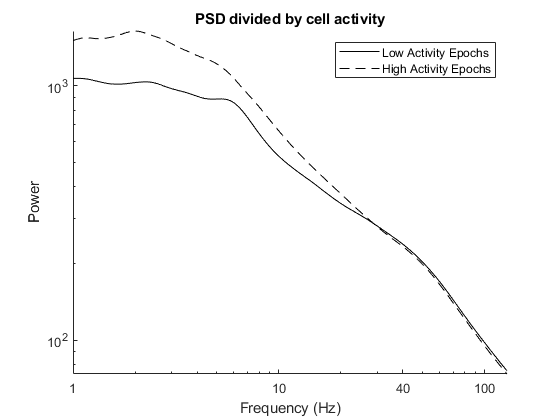

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


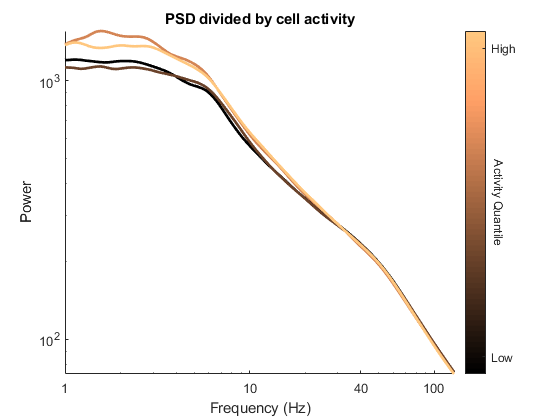

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4632(2).ID = 4632;
Animal4632(2).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4632(2).ID, Animal4632(2).cellIDs);

Animal 4632 Day 3

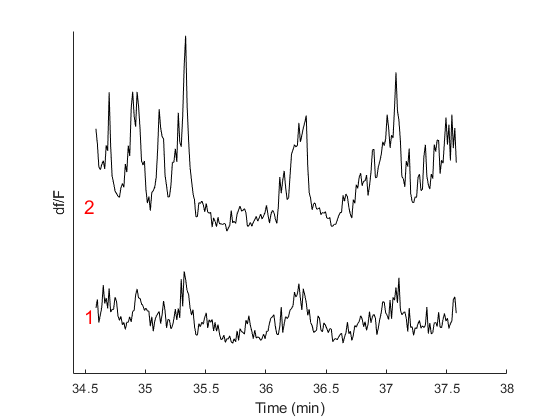

basepath = 'G:\sleep_wake_recordings\4632\JR_21_12_13_confon_GCaMP_4632\JR_21_12_13_confon_GCaMP_4632_211213_133501';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4632\JR_21_12_13_confon_GCaMP_4632\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


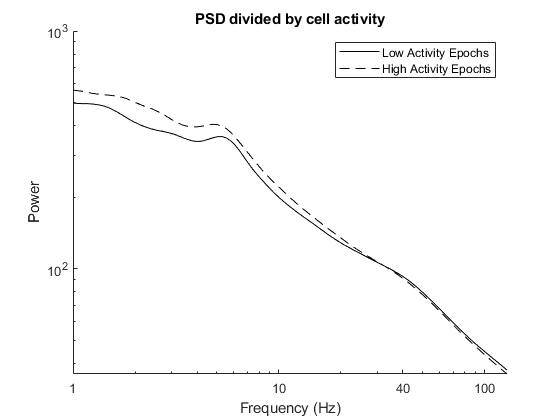

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


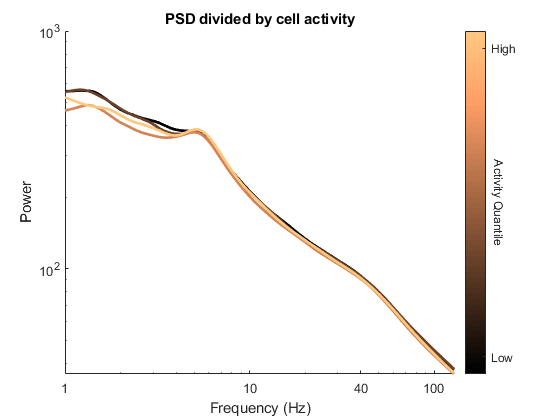

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4632(3).ID = 4632;
Animal4632(3).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4632(3).ID, Animal4632(3).cellIDs);

Animal 4632 Day 4

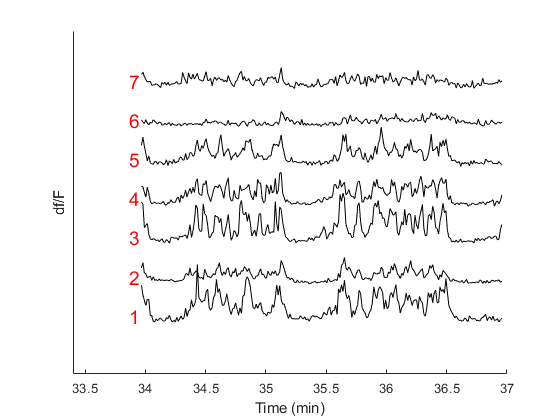

basepath = 'G:\sleep_wake_recordings\4632\JR_21_12_15_confon_GCaMP_4632\JR_21_12_15_confon_GCaMP_4632_211215_155245';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4632\JR_21_12_15_confon_GCaMP_4632\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


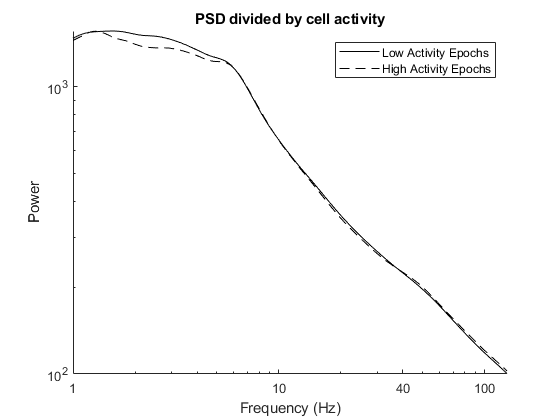

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


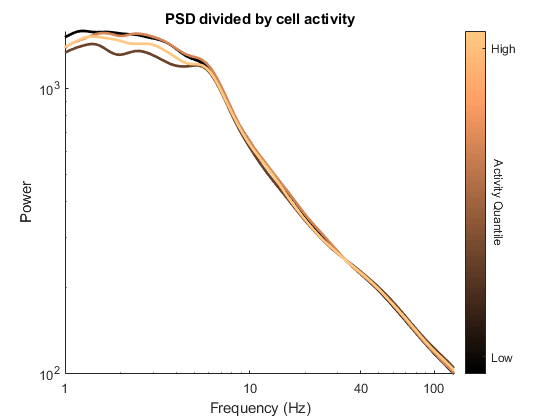

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4632(4).ID = 4632;
Animal4632(4).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4632(4).ID, Animal4632(4).cellIDs);

## Animal 4633

Animal 4633 Day 1

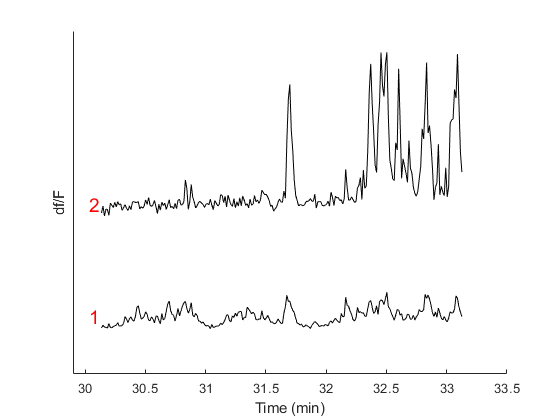

basepath = 'G:\sleep_wake_recordings\4633\JR_21_12_08_confon_GCaMP_4633\JR_21_12_08_confon_GCaMP_4633_211208_144106';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4633\JR_21_12_08_confon_GCaMP_4633\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


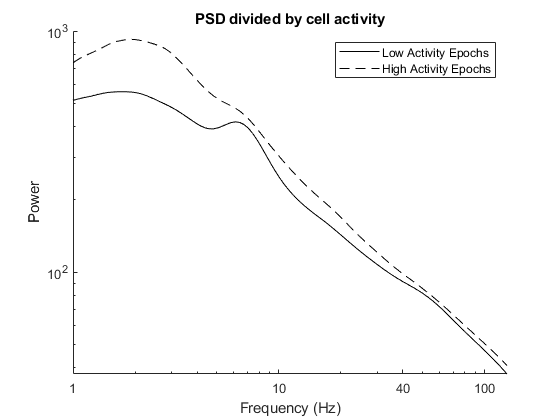

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


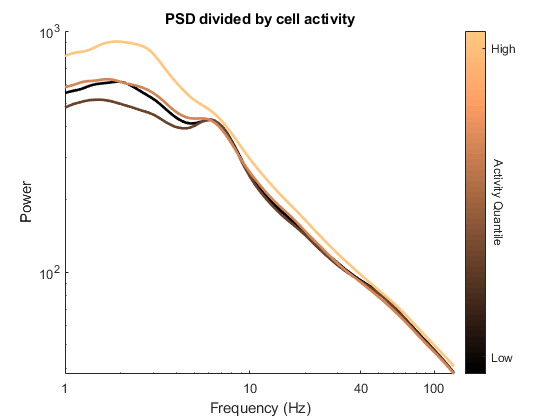

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal4633(1).ID = 4633;

% Analyze session
Animal4633(1).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4633(1).ID, Animal4633(1).cellIDs);

Animal 4633 Day 2

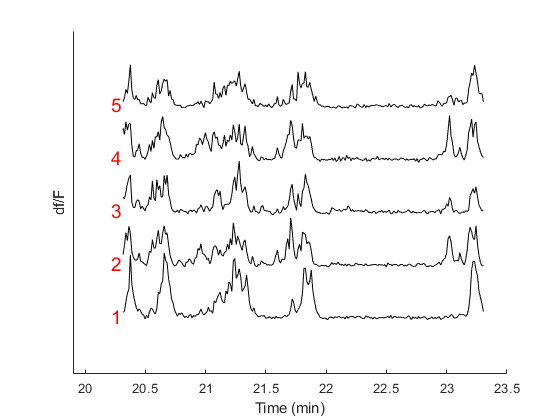

basepath = 'G:\sleep_wake_recordings\4633\JR_21_12_13_confon_GCaMP_4633\JR_21_12_13_confon_GCaMP_4633_211213_152325';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4633\JR_21_12_13_confon_GCaMP_4633\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


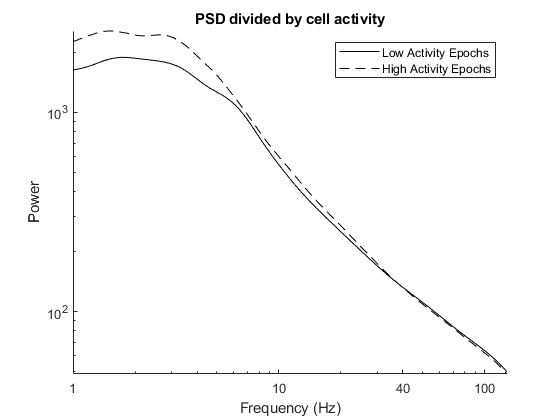

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


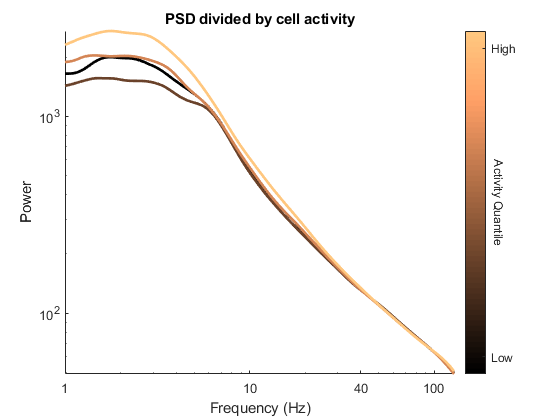

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4633(2).ID = 4633;
Animal4633(2).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4633(2).ID, Animal4633(2).cellIDs);

Animal 4633 Day 3

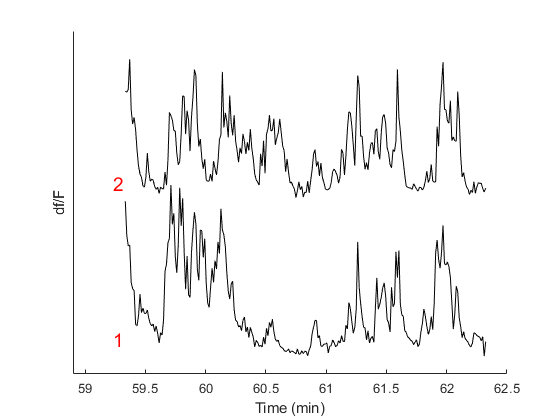

basepath = 'G:\sleep_wake_recordings\4633\JR_21_12_15_confon_GCaMP_4633\JR_21_12_15_confon_GCaMP_4633_211215_172953';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4633\JR_21_12_15_confon_GCaMP_4633\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



imgStruct.deltaF.time = imgStruct.deltaF.time(1:6000);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


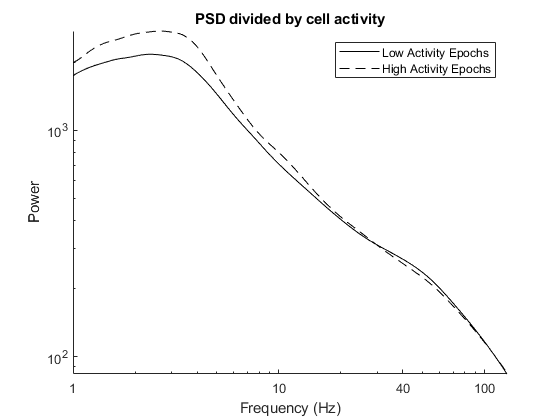

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


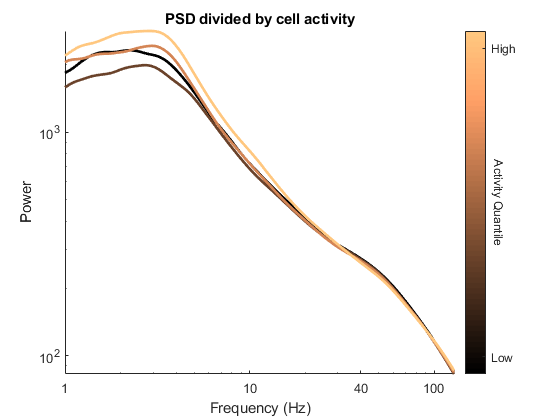

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4633(3).ID = 4633;
Animal4633(3).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4633(3).ID, Animal4633(3).cellIDs);

## Animal 4634

Animal 4634 Day 1

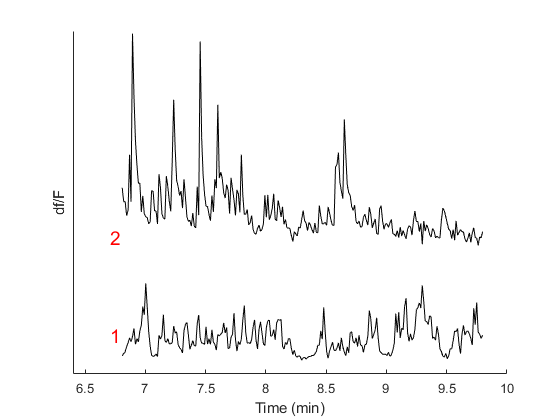

basepath = 'G:\sleep_wake_recordings\4634\JR_21_12_03_confon_GCaMP_4634\JR_21_12_03_confon_GCaMP_4634_211203_154542';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4634\JR_21_12_03_confon_GCaMP_4634\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


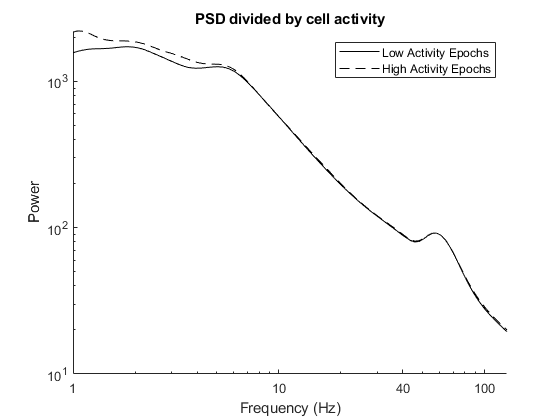

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


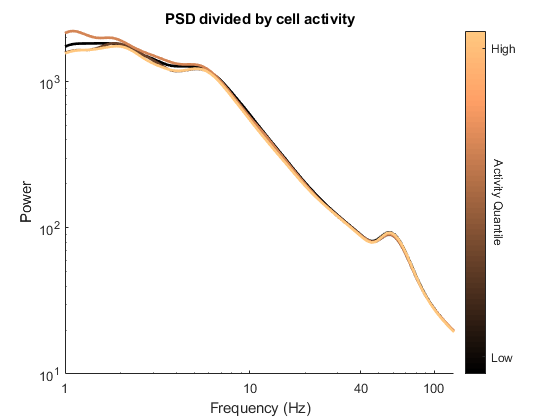

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal4634(1).ID = 4634;

% Analyze session
Animal4634(1).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4634(1).ID, Animal4634(1).cellIDs);

Animal 4634 Day 2

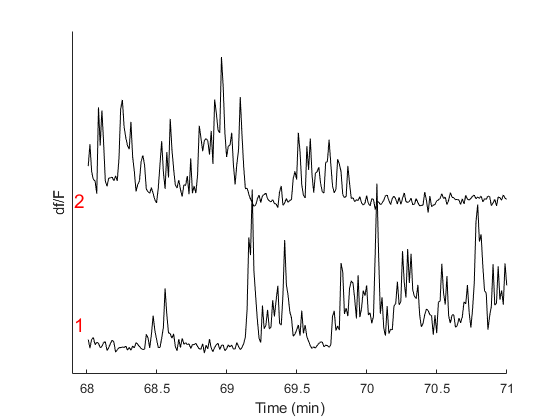

basepath = 'G:\sleep_wake_recordings\4634\JR_21_12_08_confon_GCaMP_4634\JR_21_12_08_confon_GCaMP_4634_211208_103657';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4634\JR_21_12_08_confon_GCaMP_4634\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


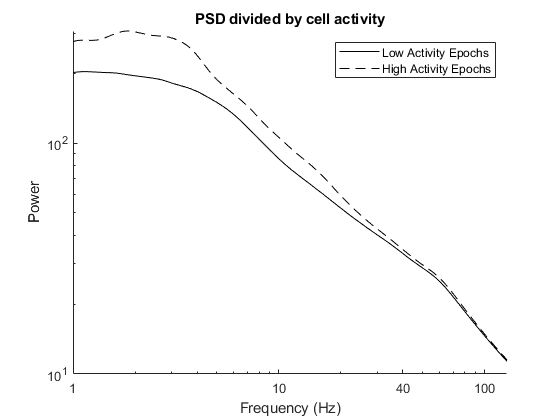

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


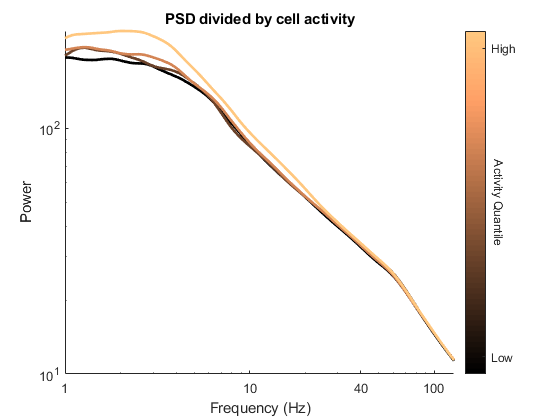

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4634(2).ID = 4634;
Animal4634(2).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4634(2).ID, Animal4634(2).cellIDs);

Animal 4634 Day 3

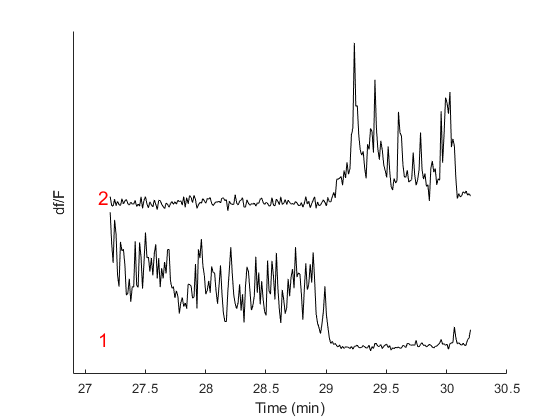

basepath = 'G:\sleep_wake_recordings\4634\JR_21_12_13_confon_GCaMP_4634\JR_21_12_13_confon_GCaMP_4634_211213_113139';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4634\JR_21_12_13_confon_GCaMP_4634\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


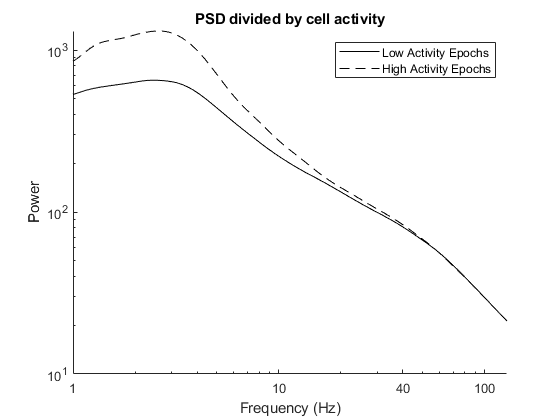

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


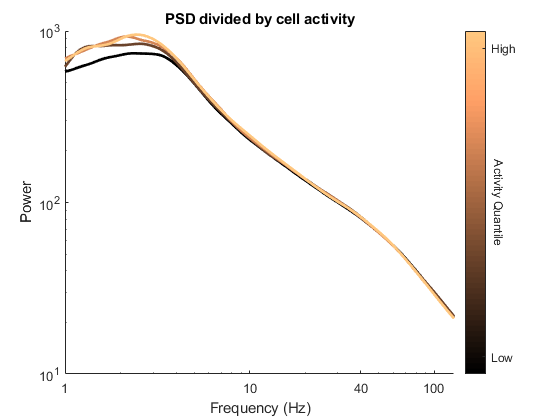

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4634(3).ID = 4634;
Animal4634(3).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4634(3).ID, Animal4634(3).cellIDs);

Animal 4634 Day 4

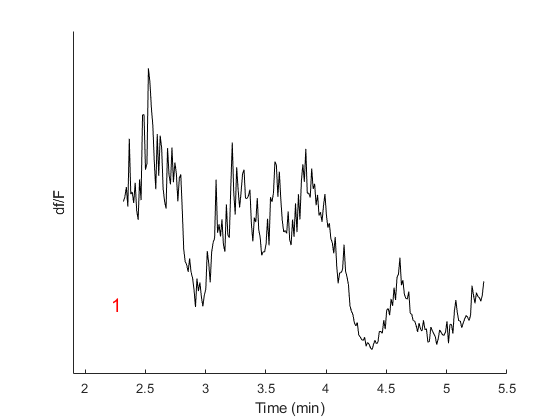

basepath = 'G:\sleep_wake_recordings\4634\JR_21_12_15_confon_GCaMP_4634\JR_21_12_15_confon_GCaMP_4634_211215_141822';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4634\JR_21_12_15_confon_GCaMP_4634\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


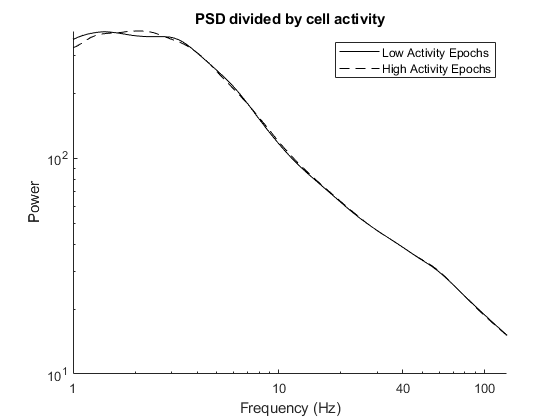

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


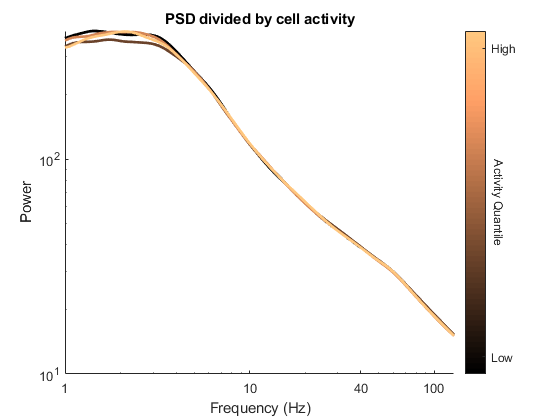

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4634(4).ID = 4634;
Animal4634(4).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4634(4).ID, Animal4634(4).cellIDs);

## Animal 4637

Animal 4637 Day 1

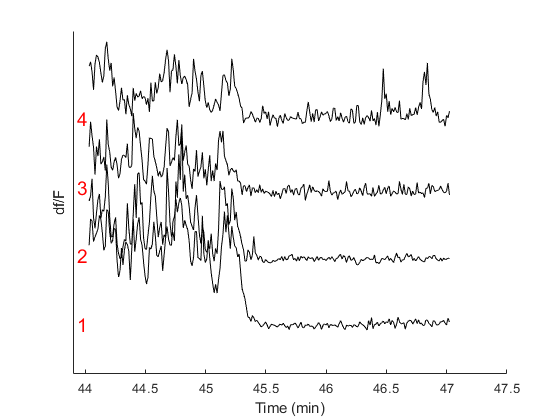

basepath = 'G:\sleep_wake_recordings\4637\JR_21_12_02_confon_GCaMP_4637\JR_21_12_02_confon_GCaMP_4637_211202_115652';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4637\JR_21_12_02_confon_GCaMP_4637\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


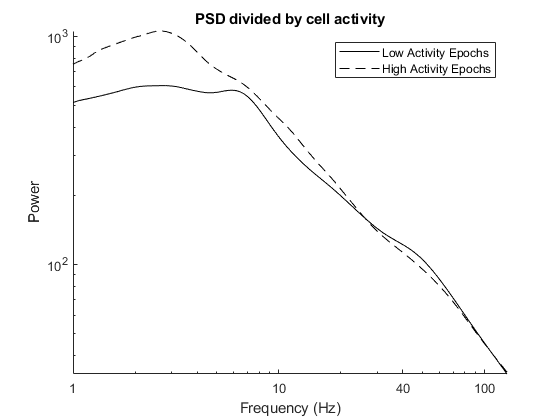

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


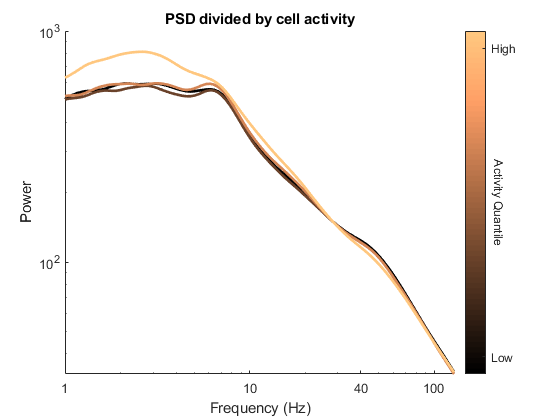

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal4637(1).ID = 4637;

% Analyze session
Animal4637(1).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4637(1).ID, Animal4637(1).cellIDs);

Animal 4637 Day 2

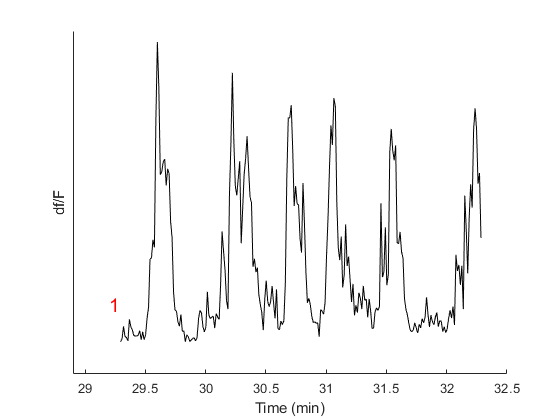

basepath = 'G:\sleep_wake_recordings\4637\JR_21_12_06_confon_GCaMP_4637\JR_21_12_06_confon_GCaMP_4637_211206_163734';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4637\JR_21_12_06_confon_GCaMP_4637\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4637(2).ID = 4637;
Animal4637(2).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4637(2).ID, Animal4637(2).cellIDs);

Loading cell type data extracted 28-Apr-2026 07:59:32


output = struct with fields:
    HighActivitySpec: [1×100 double]
     LowActivitySpec: [1×100 double]


Animal 4637 Day 3

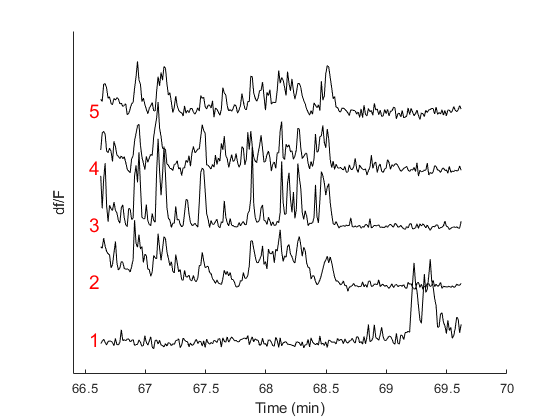

basepath = 'G:\sleep_wake_recordings\4637\JR_21_12_10_confon_GCaMP_4637\JR_21_12_10_confon_GCaMP_4637_211210_112913';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4637\JR_21_12_10_confon_GCaMP_4637\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


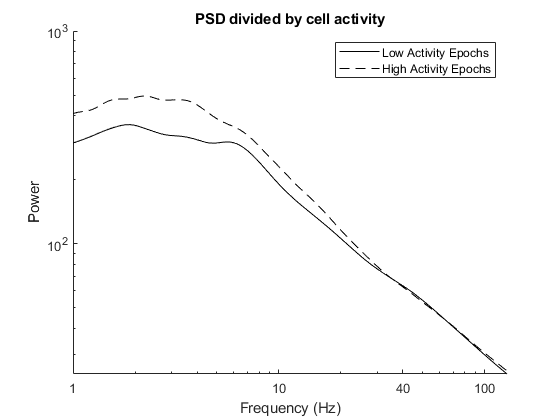

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


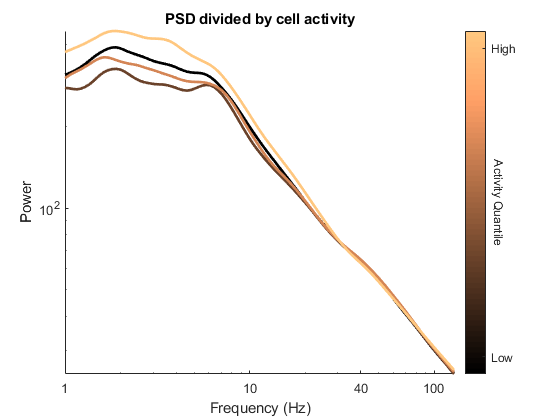

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4637(3).ID = 4637;
Animal4637(3).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4637(3).ID, Animal4637(3).cellIDs);

Animal 4637 Day 4

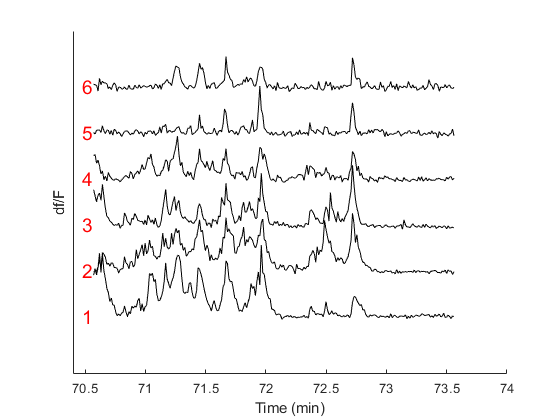

basepath = 'G:\sleep_wake_recordings\4637\JR_21_12_14_confon_GCaMP_4637\JR_21_12_14_confon_GCaMP_4637_211214_125741';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4637\JR_21_12_14_confon_GCaMP_4637\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



imgStruct.deltaF.time = imgStruct.deltaF.time(1:6287);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


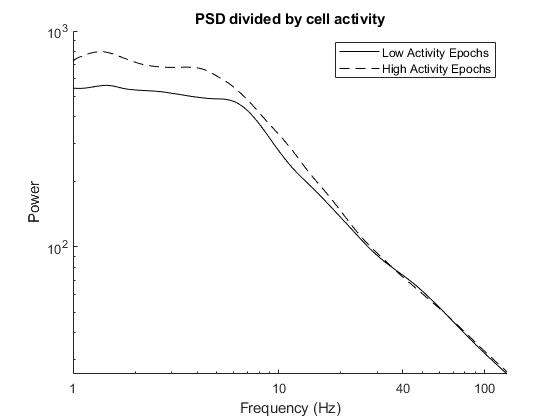

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


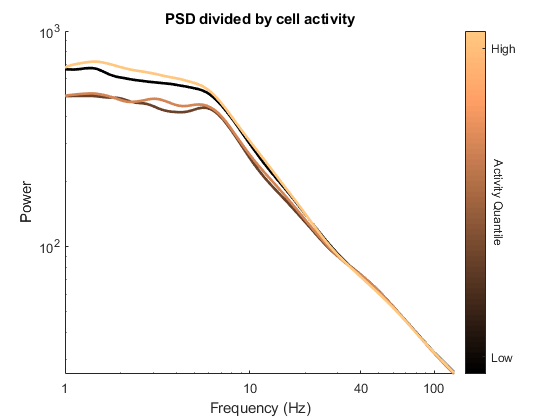

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

% Analyze session
Animal4637(4).ID = 4637;
Animal4637(4).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4637(4).ID, Animal4637(4).cellIDs);

## Animal 3300

Animal 3300 Day 1

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_03_confon_GCaMP_animal_1\JR_22_08_03_confon_GCaMP_animal_1_220803_144226';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_03_confon_GCaMP_animal_1\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");

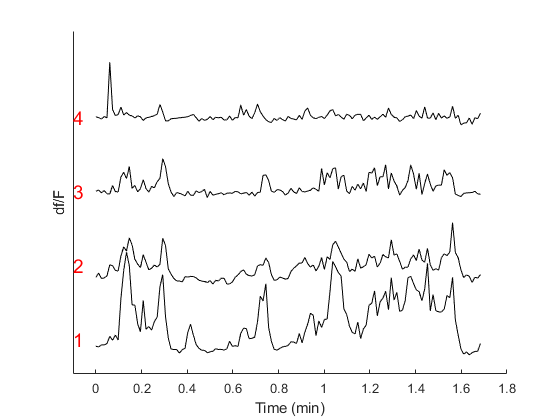

imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


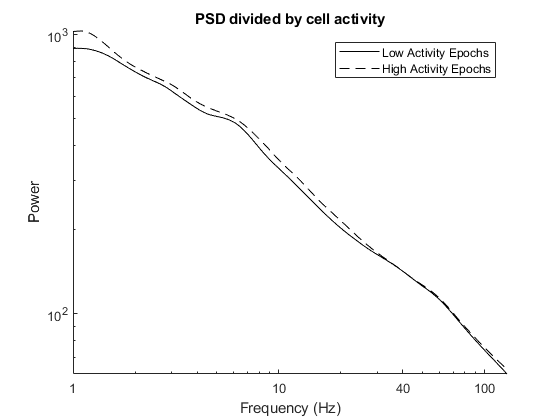

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


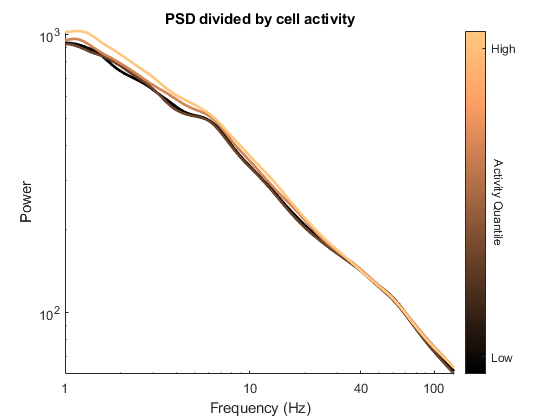

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal3300(1).ID = 3300;

% Analyze session
Animal3300(1).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal3300(1).ID, Animal3300_sleep(1).cellIDs);

Animal3300(1).cellIDs = Animal3300_sleep(1).cellIDs;

Animal 3300 Day 2

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_05_confon_GCaMP_animal_1\JR_22_08_05_confon_GCaMP_animal_1_220805_151711';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_05_confon_GCaMP_animal_1\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");

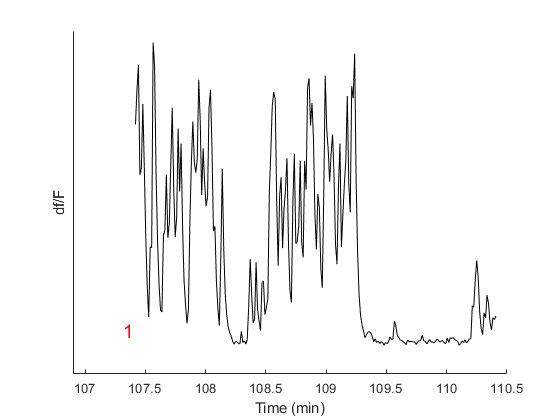

imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


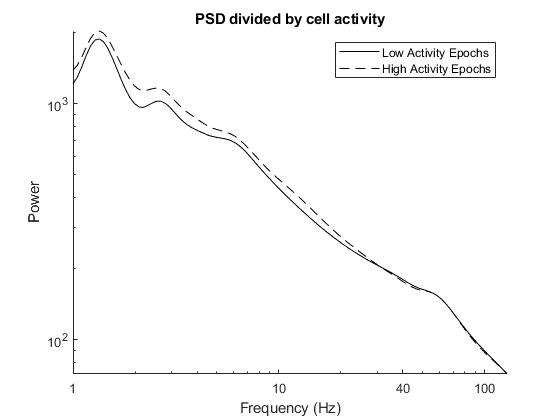

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


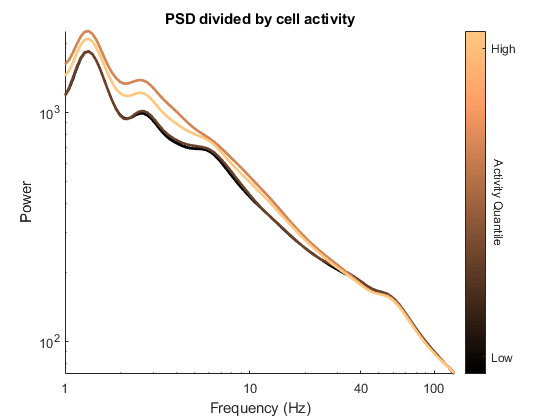

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal3300(2).ID = 3300;

% Analyze session
Animal3300(2).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal3300(2).ID, Animal3300_sleep(2).cellIDs);

Animal3300(2).cellIDs = Animal3300_sleep(2).cellIDs;

Animal 3300 Day 3

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_09_confon_GCaMP_animal_1\JR_22_08_09_confon_GCaMP_animal_1_220809_140641';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_09_confon_GCaMP_animal_1\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");

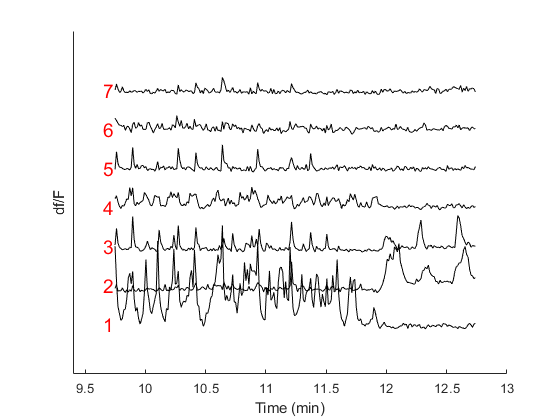

imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


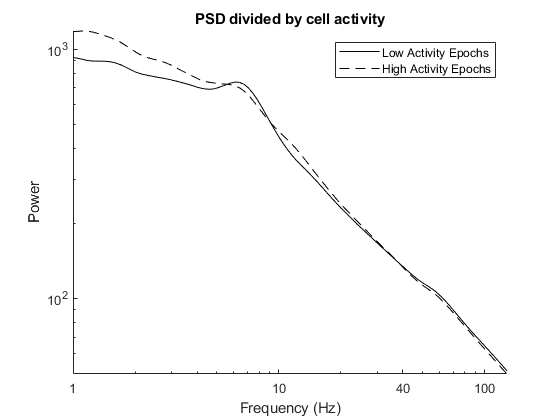

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


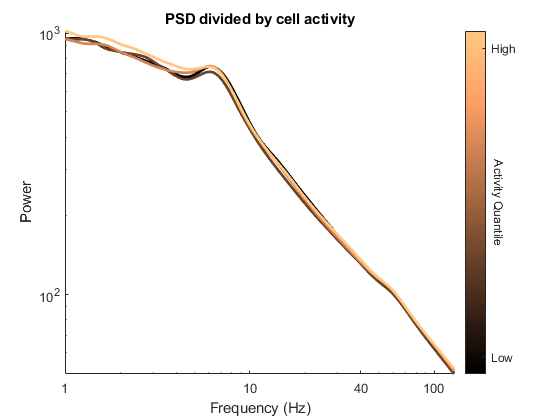

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal3300(3).ID = 3300;

% Analyze session
Animal3300(3).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal3300(3).ID, Animal3300_sleep(3).cellIDs);

Animal3300(3).cellIDs = Animal3300_sleep(3).cellIDs;

Animal 3300 Day 4

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_12_confon_GCaMP_animal_1\JR_22_08_12_confon_GCaMP_animal_1_220812_160050';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_12_confon_GCaMP_animal_1\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");

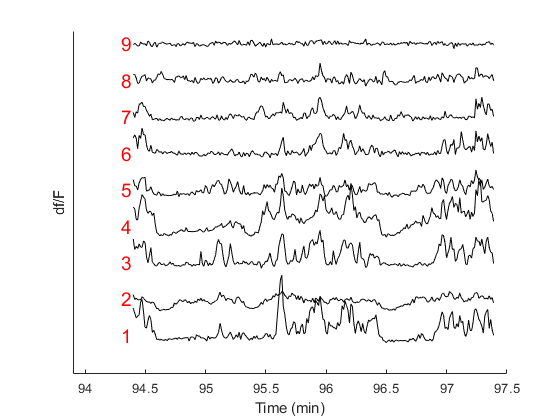

imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


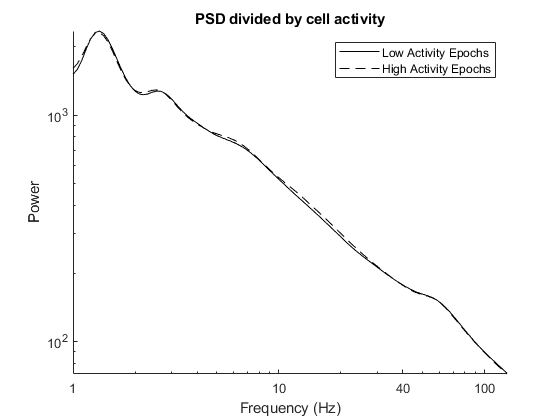

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


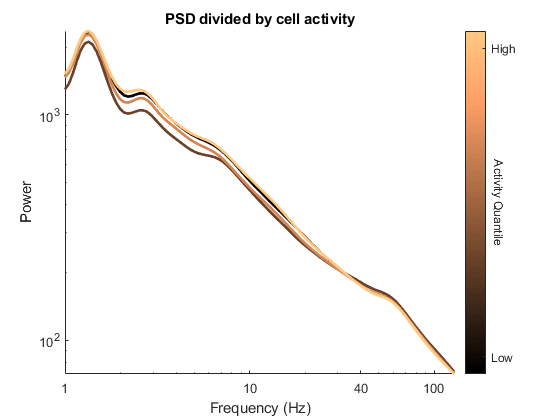

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal3300(4).ID = 3300;

% Analyze session
Animal3300(4).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal3300(4).ID, Animal3300_sleep(4).cellIDs);

Animal3300(4).cellIDs = Animal3300_sleep(4).cellIDs;

## Animal 5646

Animal 5646 Day 1

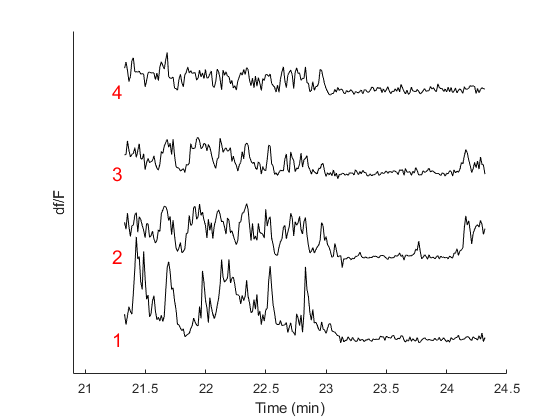

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_10_13_confon_GCaMP_animal_5646\JR_22_10_13_confon_GCaMP_animal_5646_221013_152101';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_10_13_confon_GCaMP_animal_5646\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


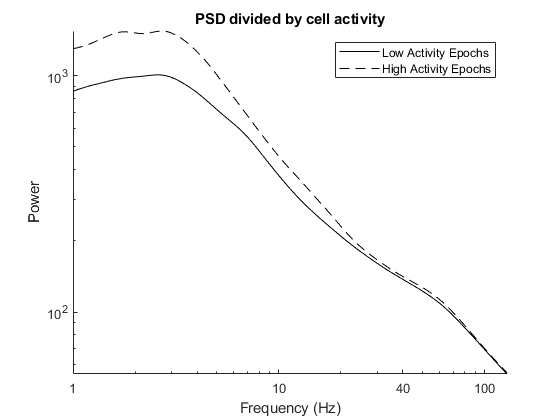

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


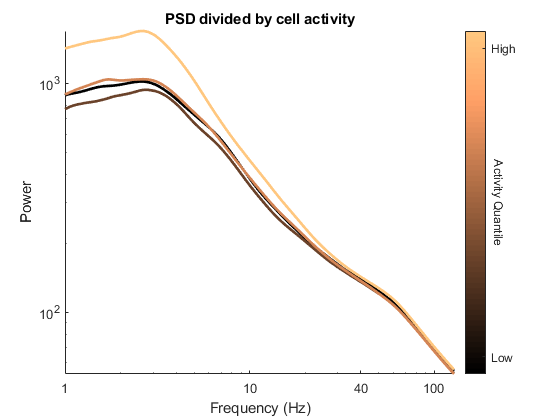

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal5646(1).ID = 5646;

% Analyze session
Animal5646(1).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal5646(1).ID, Animal5646_sleep(1).cellIDs);

Animal5646(1).cellIDs = Animal5646_sleep(1).cellIDs;

## Animal 4094

Animal 4094 Day 1

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\4094\09202022_SOMnNOS\Test_Vehicle_220920_154142';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\4094\09202022_SOMnNOS\field1';

imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(1:14,'basepath',basepath);

Loading Channels 1   2   3   4   5   6   7   8   9  10  11  12  13  14 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


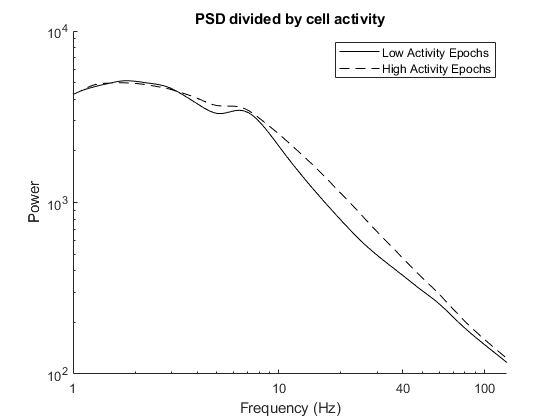

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


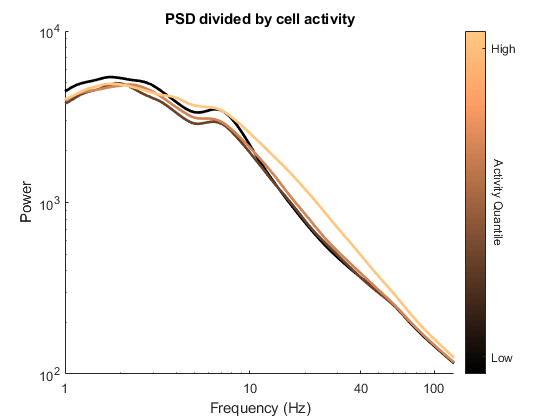

lfpReref = lfp;
lfpReref.data = lfp.data; % - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal4094(1).ID = 4094;

% Analyze session
Animal4094(1).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal4094(1).ID, Animal4094_sleep(1).cellIDs);

Animal4094(1).cellIDs = Animal4094_sleep(1).cellIDs;

## Animal 5628

Animal 5628 Day 1

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\11232022_SOMnNOS\5628_AFDX_221123_152657';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\11232022_SOMnNOS\5628_AFDX';

imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);

imgStruct.AlignedData.faceMotion.data(500) = mean(imgStruct.AlignedData.faceMotion.data); % removing outlier

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP([0:2 12:15],'basepath',basepath);

Loading Channels 0   1   2  12  13  14  15 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


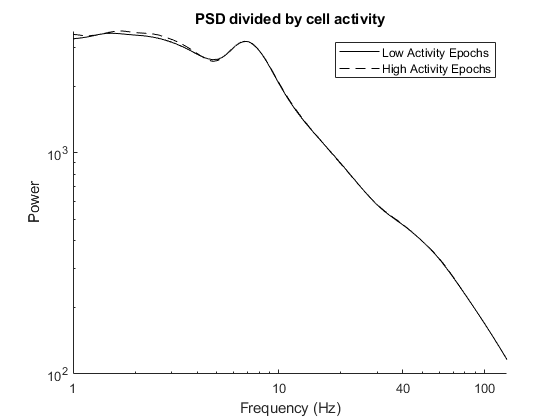

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


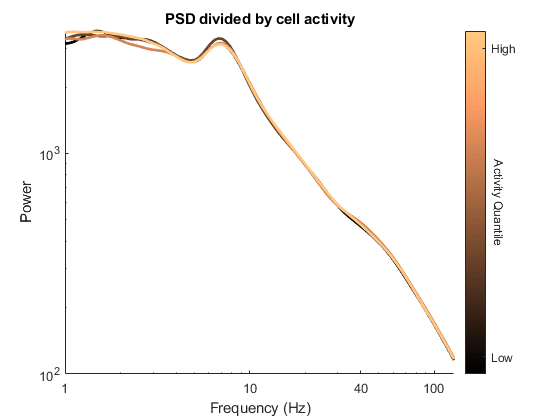

lfpReref = lfp;
lfpReref.data = lfp.data; % - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal5628(1).ID = 5628;

% Analyze session
Animal5628(1).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal5628(1).ID, Animal5628_sleep(1).cellIDs);

Animal5628(1).cellIDs = Animal5628_sleep(1).cellIDs;

Animal 5628 Day 2

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\12092022_SOMnNOS\Pre_injection\AFDX1mM_221209_125812';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\12092022_SOMnNOS\Pre_injection\preAFDX';

imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP([1:2 12:15],'basepath',basepath);

Loading Channels 1   2  12  13  14  15 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


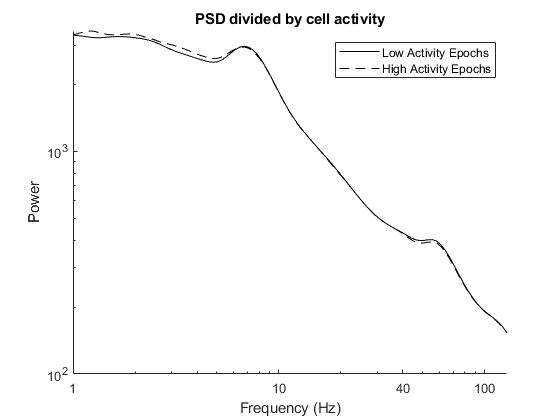

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


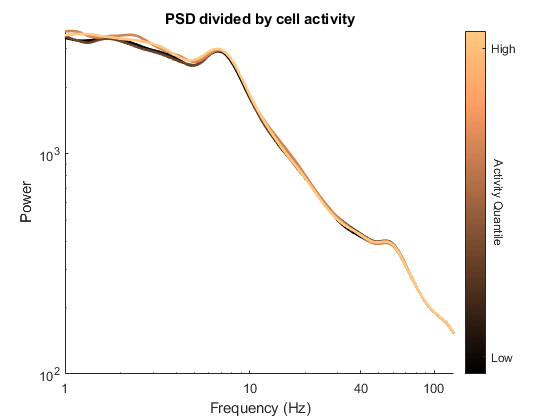

lfpReref = lfp;
lfpReref.data = lfp.data; % - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal5628(2).ID = 5628;

% Analyze session
Animal5628(2).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal5628(2).ID, Animal5628_sleep(2).cellIDs);

Animal5628(2).cellIDs = Animal5628_sleep(2).cellIDs;

Animal 5628 Day 3

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\12212022_SOMnNOS\AFDX1mM_221221_143557';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\12212022_SOMnNOS\AFDX_tif';

imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP([1:2 12:15],'basepath',basepath);

Loading Channels 1   2  12  13  14  15 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


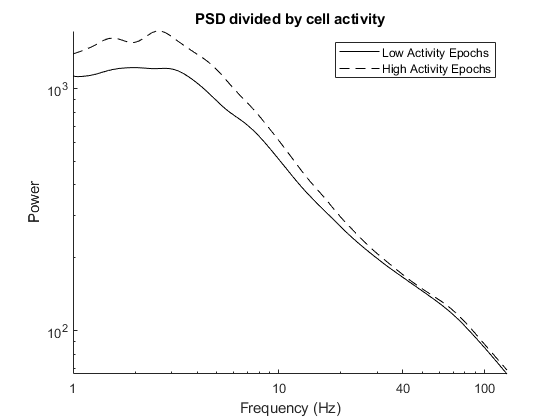

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


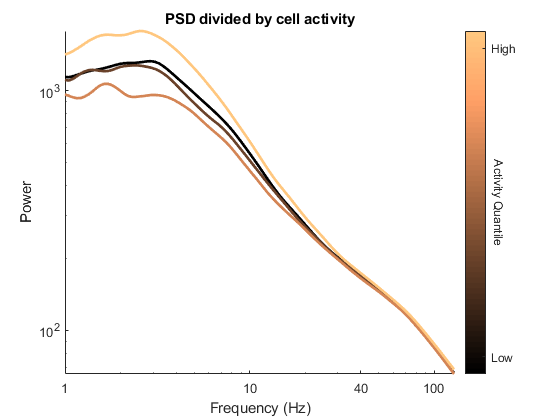

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal5628(3).ID = 5628;

% Analyze session
Animal5628(3).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal5628(3).ID, Animal5628_sleep(3).cellIDs);

Animal5628(3).cellIDs = Animal5628_sleep(3).cellIDs;

Animal 5628 Day 4

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\12222022_SOMnNOS\AFDX1mM_221222_150023';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\12222022_SOMnNOS\AFDX_tif';

imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP([1:2 12:15],'basepath',basepath);

Loading Channels 1   2  12  13  14  15 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


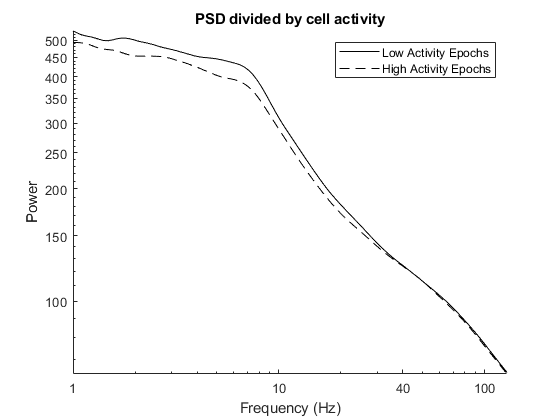

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


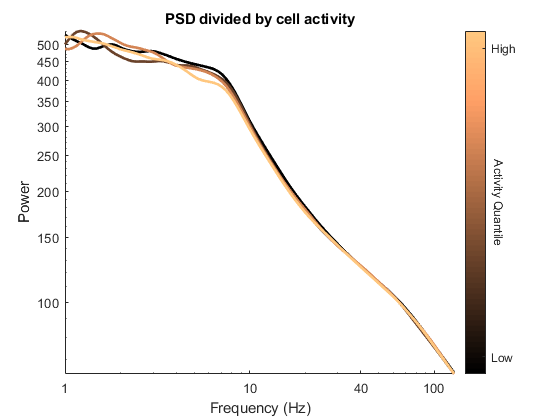

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal5628(4).ID = 5628;

% Analyze session
Animal5628(4).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal5628(4).ID, Animal5628_sleep(4).cellIDs);

Animal5628(4).cellIDs = Animal5628_sleep(4).cellIDs;

% Options for data alignment
ops.cameraTriggerChan = 10;
ops.treadmillChan = 11;
ops.overwrite = false;
ops1.method = 'baseline';

## Animal 7776

Animal 7776 Day 1

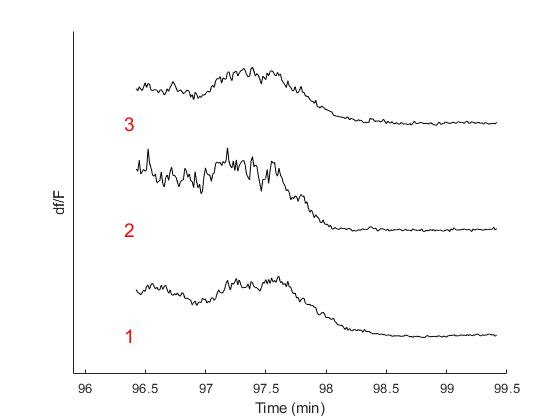

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240416_150720';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240416_150720\Imaging_04_16_2024_85um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP([0:1 7],'basepath',basepath);

Loading Channels 0  1  7 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


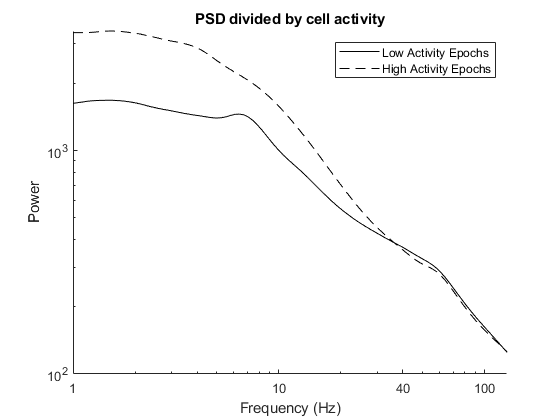

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


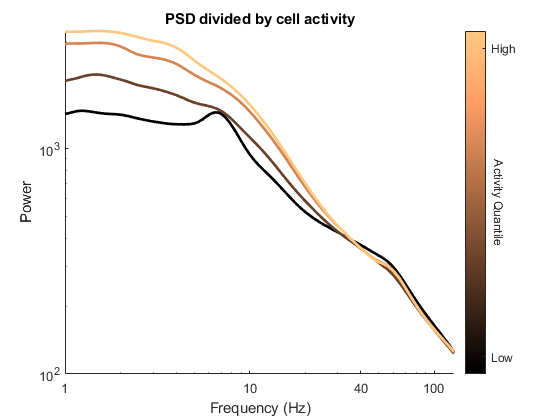

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal7776(1).ID = 7776;
Animal7776(1).cellIDs = 1:3;

% Analyze session
Animal7776(1).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal7776(1).ID, Animal7776(1).cellIDs);

Animal 7776 Day 2

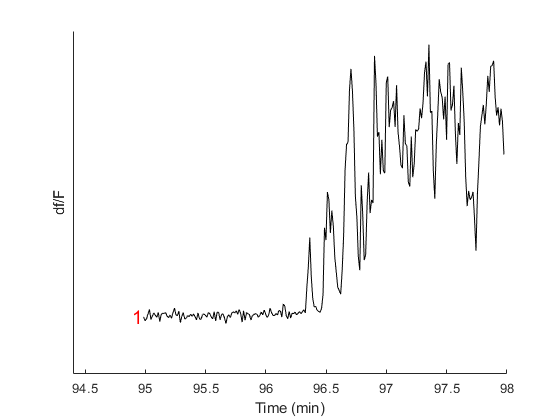

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240417_114748';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240417_114748\Imaging_04_17_2024_200um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP([0:1 7],'basepath',basepath);

Loading Channels 0  1  7 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


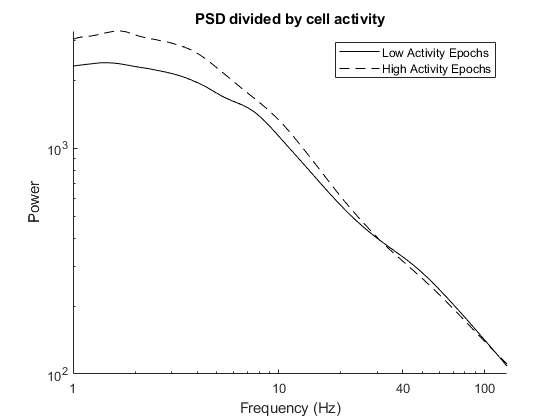

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


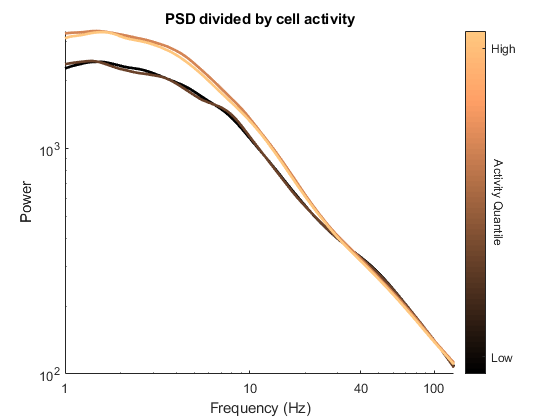

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal7776(2).ID = 7776;
Animal7776(2).cellIDs = 4;

% Analyze session
Animal7776(2).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal7776(2).ID, Animal7776(2).cellIDs);

Animal 7776 Day 3

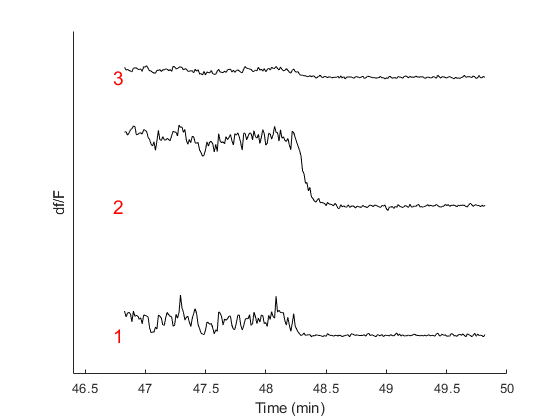

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240418_115444';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240418_115444\Imaging_04_18_2024_15um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP([0:1 7],'basepath',basepath);

Loading Channels 0  1  7 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


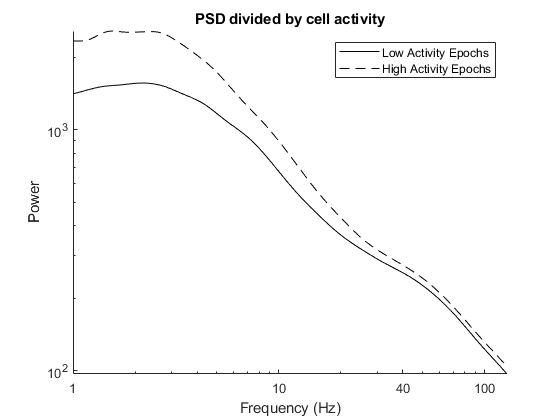

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


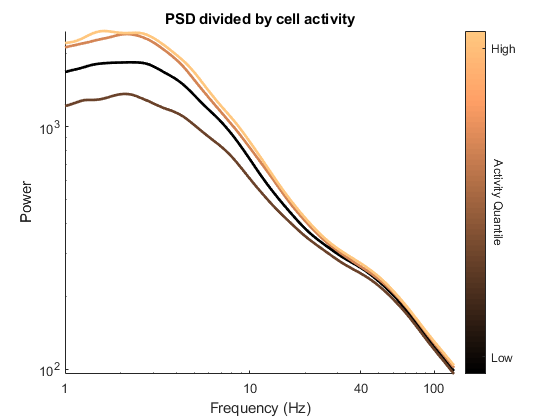

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal7776(3).ID = 7776;
Animal7776(3).cellIDs = 5:7;

% Analyze session
Animal7776(3).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal7776(3).ID, Animal7776(3).cellIDs);

Animal 7776 Day 4

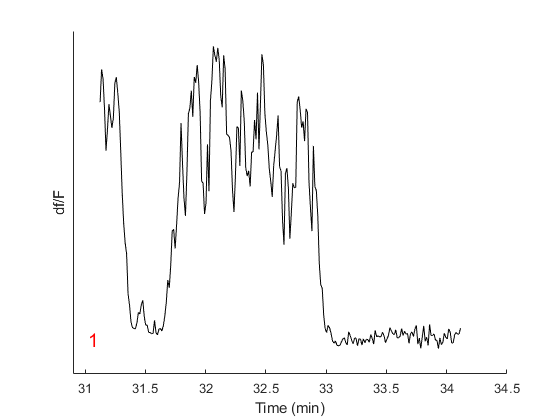

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240419_155705';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240419_155705\Imaging_04_19_2024_70um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP([0:1 7],'basepath',basepath);

Loading Channels 0  1  7 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


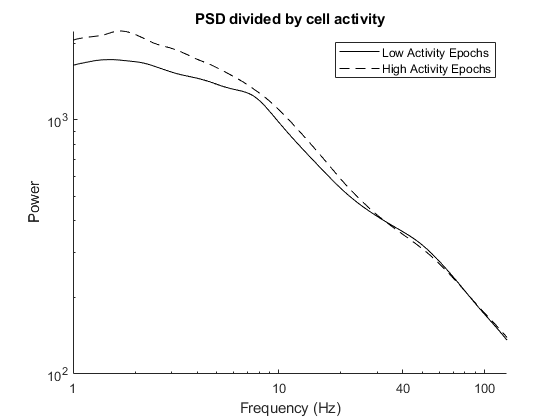

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


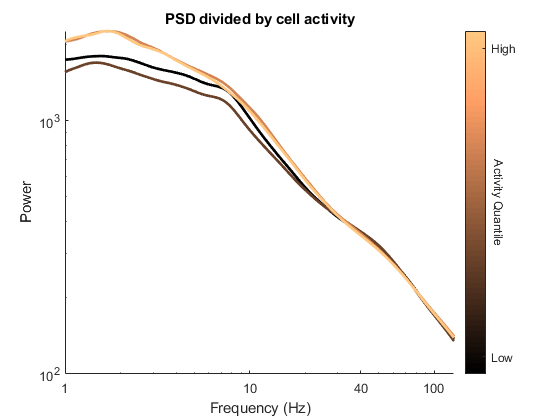

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal7776(4).ID = 7776;
Animal7776(4).cellIDs = 8;

% Analyze session
Animal7776(4).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal7776(4).ID, Animal7776(4).cellIDs);

## Animal 7777

Animal 7777 Day 1

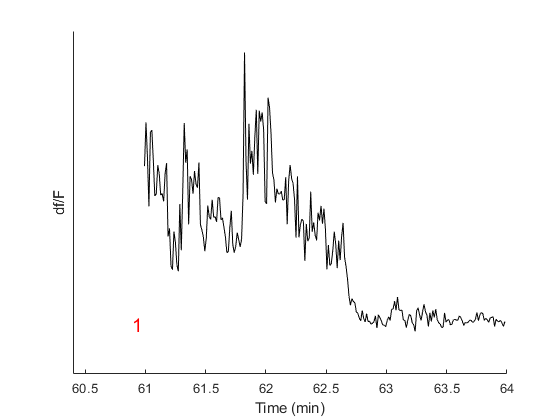

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7777\7777_240501_160828';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7777\7777_240501_160828\05-01-2024-30um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP([0:7],'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6  7 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


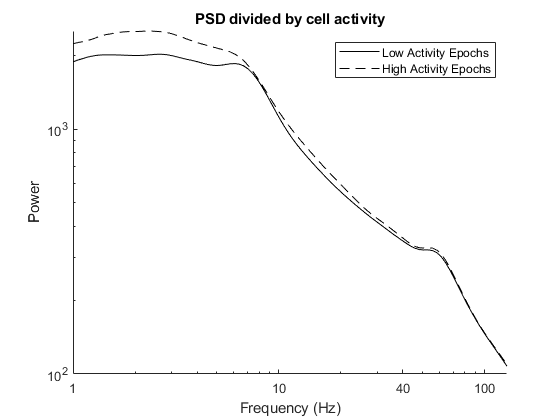

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


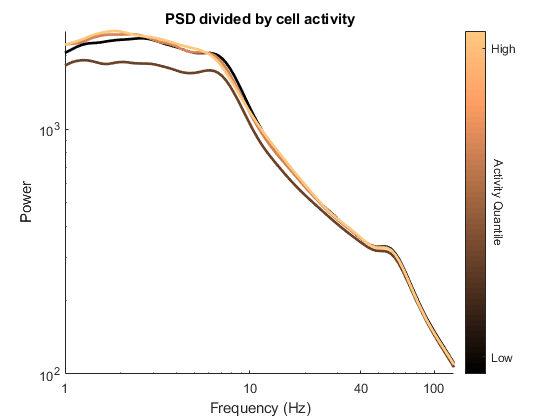

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal7777(1).ID = 7777;
Animal7777(1).cellIDs = 1;

% Analyze session
Animal7777(1).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal7777(1).ID, Animal7777(1).cellIDs);

Animal 7777 Day 2

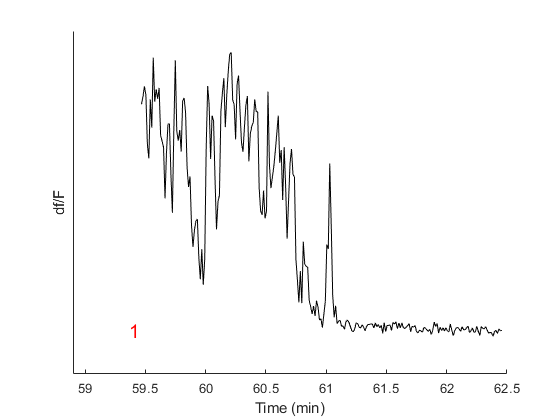

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7777\7777_240508_144803';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7777\7777_240508_144803\Imaging_05-08-2024-80um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP([0:7],'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6  7 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


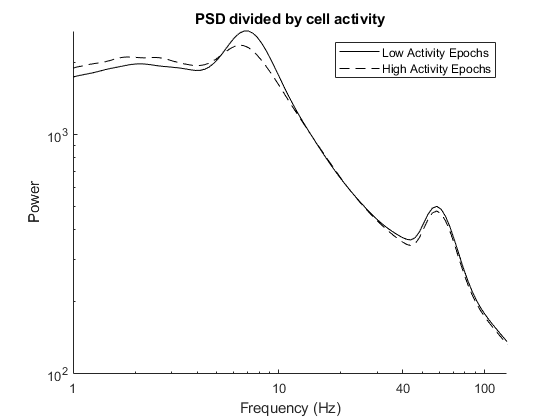

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


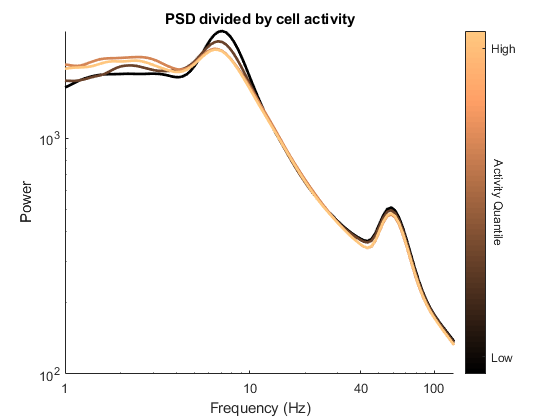

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal7777(2).ID = 7777;
Animal7777(2).cellIDs = 2;

% Analyze session
Animal7777(2).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal7777(2).ID, Animal7777(2).cellIDs);

## Animal 7992

Animal 7992 Day 1

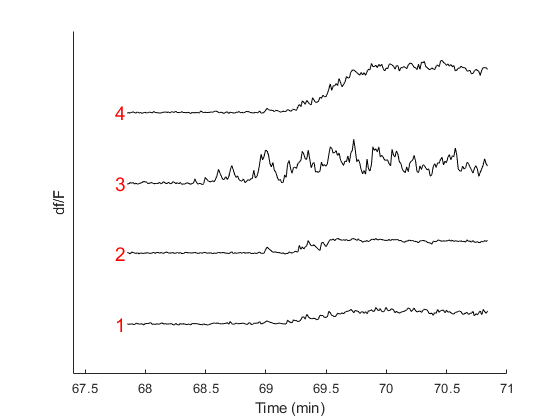

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240416_120003';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240416_120003\Imaging_04_16_2024_70um_000';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP([0:7],'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6  7 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


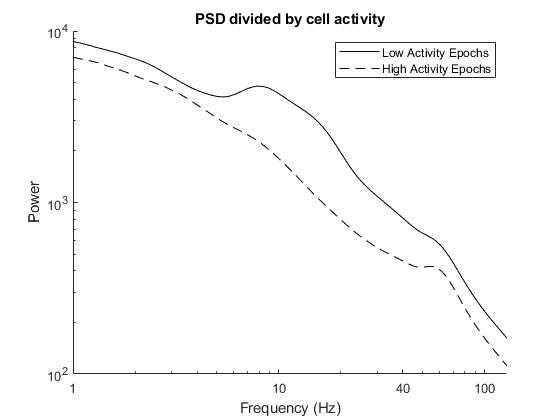

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


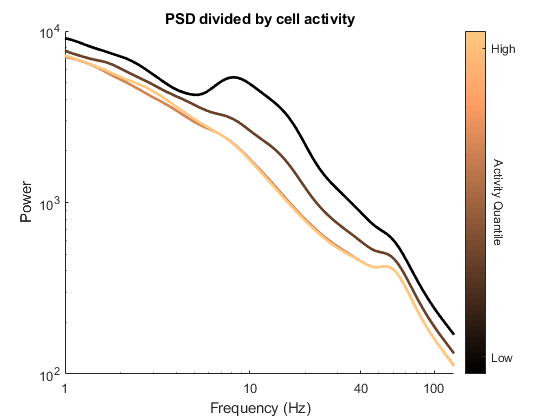

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal7992(1).ID = 7992;
Animal7992(1).cellIDs = 1:4;

% Analyze session
Animal7992(1).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal7992(1).ID, Animal7992(1).cellIDs);

Animal 7992 Day 2

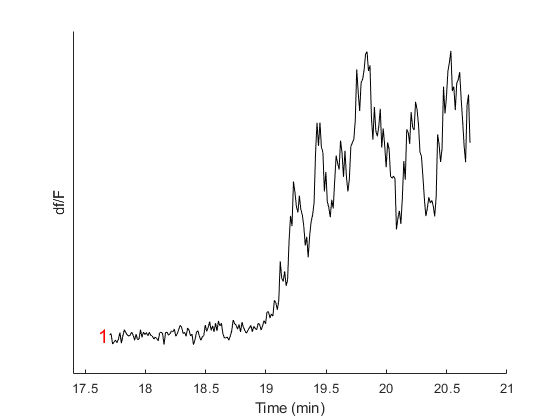

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240418_143030';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240418_143030\Imaging_04_18_2024_10um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP([0:7],'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6  7 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


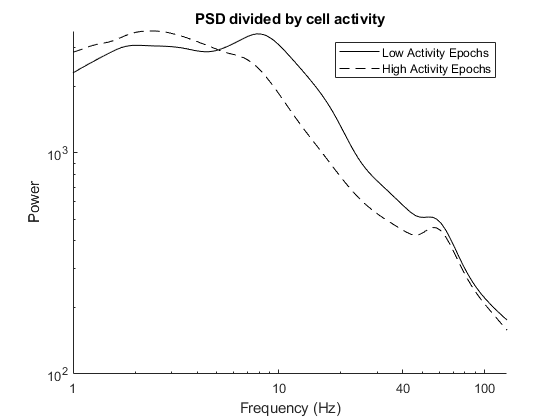

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


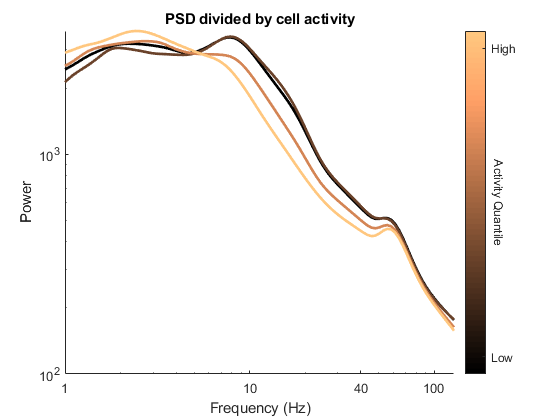

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal7992(2).ID = 7992;
Animal7992(2).cellIDs = 5;

% Analyze session
Animal7992(2).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal7992(2).ID, Animal7992(2).cellIDs);

Animal 7992 Day 3

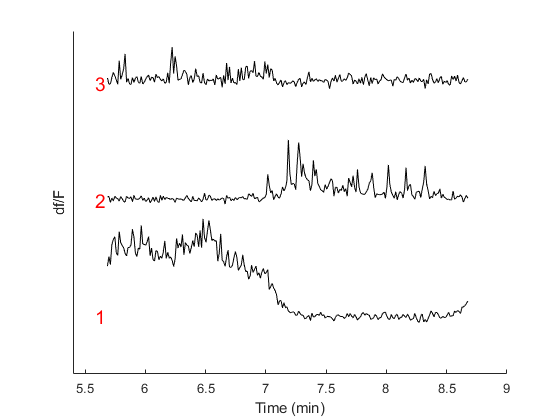

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240419_132238';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240419_132238\Imaging_04_19_2024_155um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP([0:7],'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6  7 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


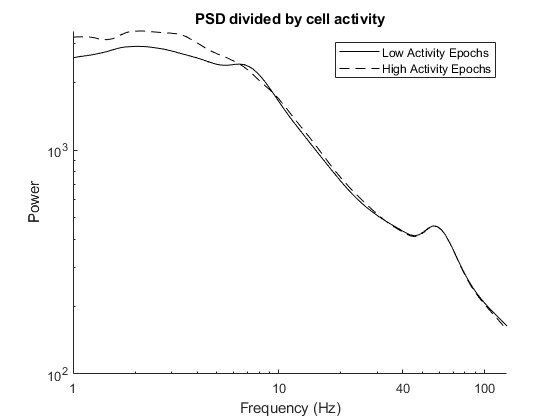

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


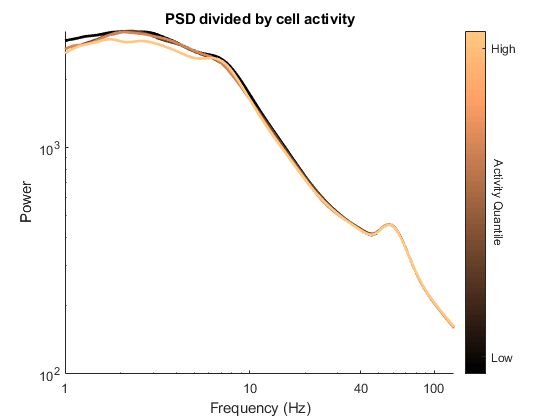

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal7992(3).ID = 7992;
Animal7992(3).cellIDs = 6:8;

% Analyze session
Animal7992(3).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal7992(3).ID, Animal7992(3).cellIDs);

Animal 7992 Day 4

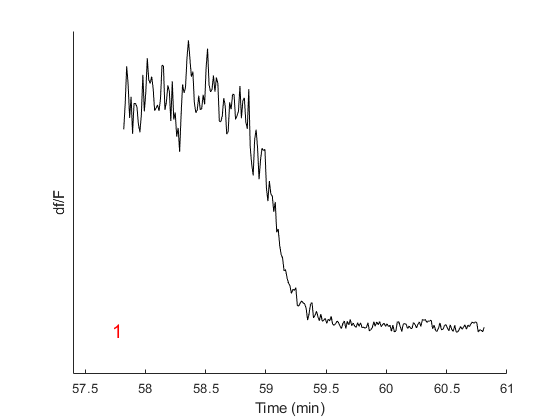

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240422_124051';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240422_124051\Imaging_04_22_2024_140um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP([0:7],'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6  7 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


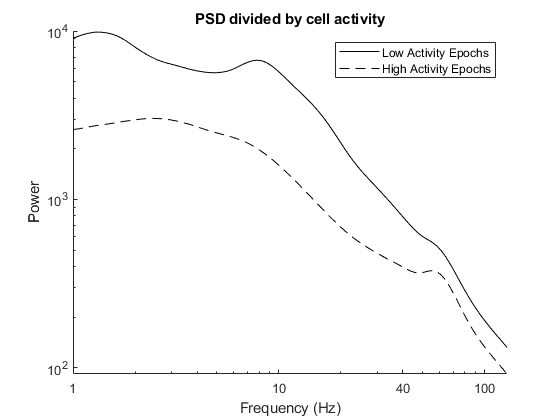

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


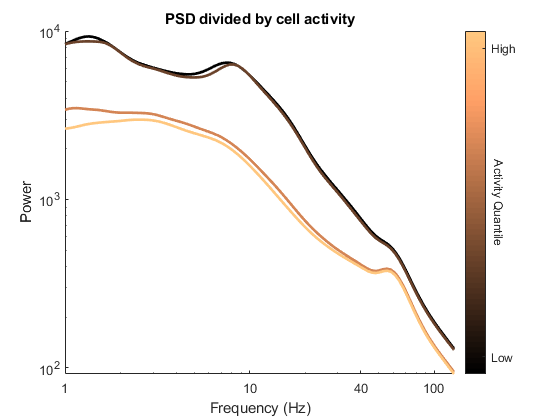

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal7992(4).ID = 7992;
Animal7992(4).cellIDs = 9;

% Analyze session
Animal7992(4).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal7992(4).ID, Animal7992(4).cellIDs);

## Animal 7995

Animal 7995 Day 1

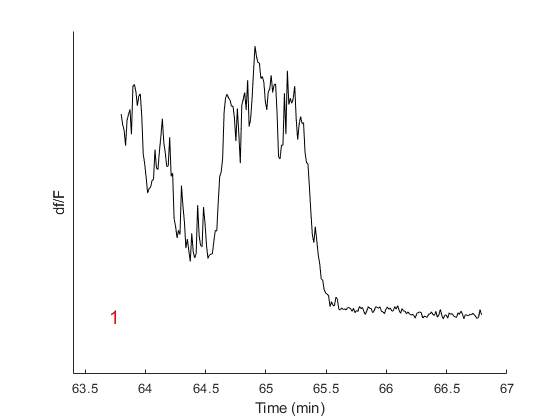

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7995\7995_240501_125221';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7995\7995_240501_125221\Imaging_05-01-2024-0um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP([0:7],'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6  7 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


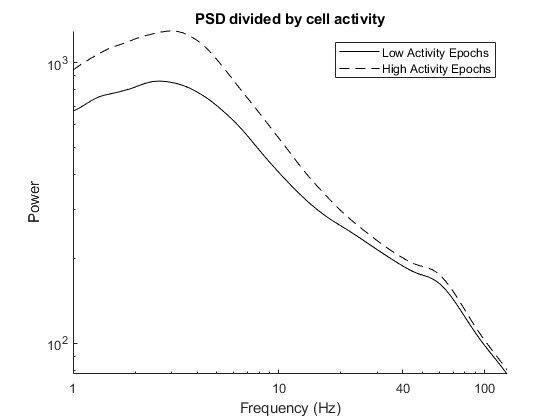

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


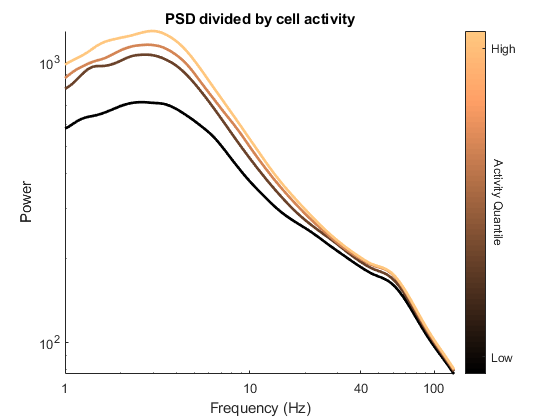

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal7995(1).ID = 7995;
Animal7995(1).cellIDs = 1;

% Analyze session
Animal7995(1).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal7995(1).ID, Animal7995(1).cellIDs);

Animal 7995 Day 2

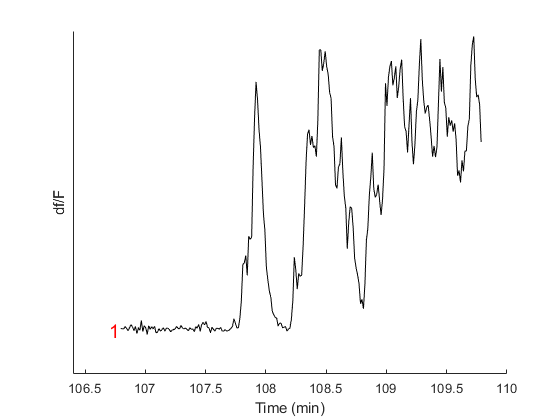

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7995\7995_240514_144726';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7995\7995_240514_144726\Imaging_05-14-2024-170um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP([0:7],'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6  7 (0-indexing, a la Neuroscope)
loading LFP file...


Loading cell type data extracted 28-Apr-2026 07:59:32
Calculating binary division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


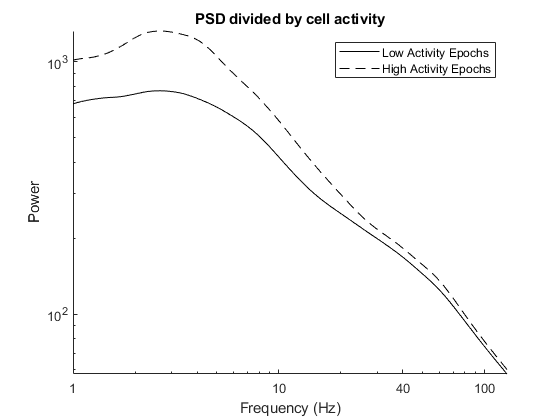

Calculating quantile division spectra...
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 
Wavelet Frequency (of 100): DONE! 


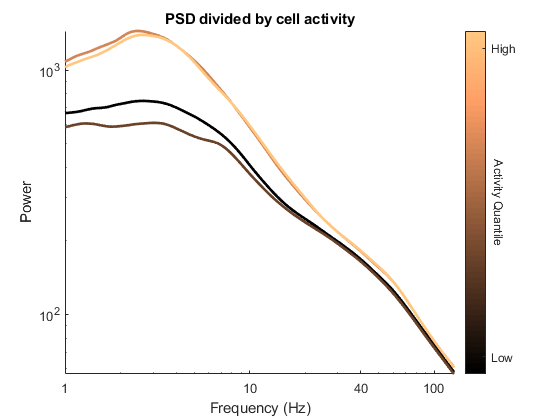

lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
SWChan = SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID;

Animal7995(2).ID = 7995;
Animal7995(2).cellIDs = 2;

% Analyze session
Animal7995(2).output = analyzeSpectrum(lfpReref,imgStruct, SWChan, Animal7995(2).ID, Animal7995(2).cellIDs);

% Combine across animals
output = combineAcrossAnimals([Animal4612, Animal4621, Animal4627, Animal4632, Animal4633, Animal4634, Animal4637,...
    Animal3300, Animal5646, Animal4094, Animal5628, Animal7776, Animal7777, Animal7992, Animal7995]);

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

% Load cell type groupings and cell UIDs
% load('D:\Dropbox (EinsteinMed)\Jacob\data and docs\MATLAB\live_scripts\SST_nNOS_sleep_imaging\arousalCorr.mat')
% 
% [~, uniqueCellInds] = unique(cellUID);
% type1Inds = intersect(uniqueCellInds, find(cellGroup == 1));

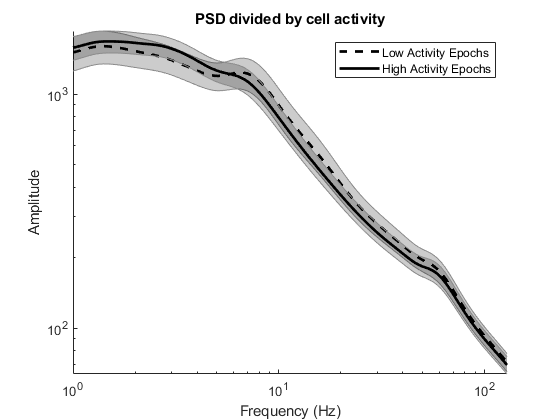


figure; hold on
shadedErrorBar(output.freqs, mean(output.LASpec, 1, 'omitnan'),...
    std(output.LASpec, 0, 1, 'omitnan')/sqrt(size(output.LASpec,1)), 'lineprops', {'k--', 'linewidth', 2 })
shadedErrorBar(output.freqs, mean(output.HASpec, 1, 'omitnan'),...
    std(output.HASpec, 0, 1, 'omitnan')/sqrt(size(output.HASpec,1)), 'lineprops', {'k-', 'linewidth', 2 })
set(gca,'YScale','log')
set(gca,'XScale','log')
ylabel('Amplitude')
xlabel('Frequency (Hz)')
legend({'Low Activity Epochs', 'High Activity Epochs'})
title('PSD divided by cell activity')

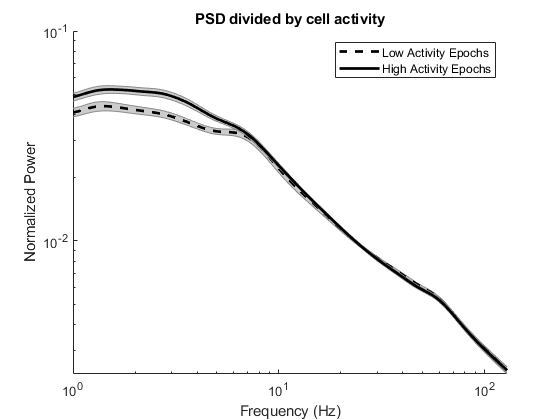

normSpec.mean = (output.HASpec + output.LASpec) ./2; 
normSpec.HA = (output.HASpec ./ trapz(output.freqs, normSpec.mean, 2));
normSpec.LA = (output.LASpec ./ trapz(output.freqs, normSpec.mean, 2));

figure; hold on
shadedErrorBar(output.freqs, mean(normSpec.LA, 1, 'omitnan'),...
    std(normSpec.LA, 0, 1, 'omitnan')/sqrt(size(normSpec.LA,1)), 'lineprops', {'k--', 'linewidth', 2 })
shadedErrorBar(output.freqs, mean(normSpec.HA, 1, 'omitnan'),...
    std(normSpec.HA, 0, 1, 'omitnan')/sqrt(size(normSpec.HA,1)), 'lineprops', {'k-', 'linewidth', 2 })
set(gca,'YScale','log')
set(gca,'XScale','log')
ylabel('Normalized Power')
xlabel('Frequency (Hz)')
legend({'Low Activity Epochs', 'High Activity Epochs'})
title('PSD divided by cell activity')

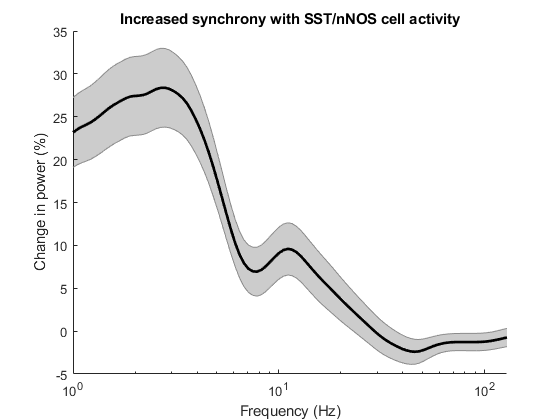

figure; hold on
shadedErrorBar(output.freqs, mean(normSpec.HA ./ normSpec.LA, 1, 'omitnan')*100 - 100,...
    std(normSpec.HA ./ normSpec.LA, 0, 1, 'omitnan')/sqrt(size(normSpec.LA,1))*100, 'lineprops', {'k-', 'linewidth', 2 })
% set(gca,'YScale','log')
set(gca,'XScale','log')
ylabel('Change in power (%)')
xlabel('Frequency (Hz)')
% legend({'Low Activity Epochs', 'High Activity Epochs'})
title('Increased synchrony with SST/nNOS cell activity')

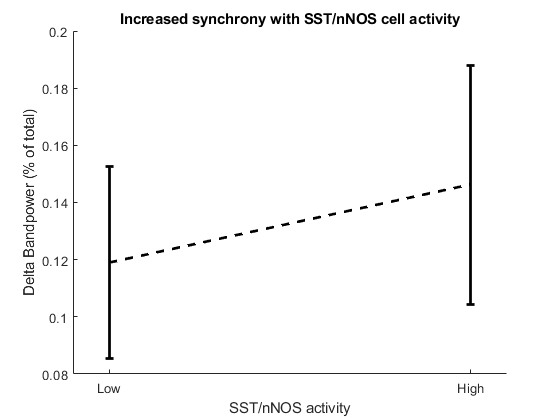

deltaInds = output.freqs <= 4;
deltaBand.HA = trapz(output.freqs(deltaInds), normSpec.HA(:,deltaInds),2);
deltaBand.LA = trapz(output.freqs(deltaInds), normSpec.LA(:,deltaInds),2);

figure
errorbar(1:2, [mean(deltaBand.LA, 'omitnan') mean(deltaBand.HA, 'omitnan')], ...
    [std(deltaBand.LA, 'omitnan') std(deltaBand.HA, 'omitnan')],'k--','LineWidth',2)
xlim([.9 2.1])
ylabel('Delta Bandpower (% of total)')
xticks(1:2)
xticklabels({'Low', 'High'})
xlabel('SST/nNOS activity')
box off
title('Increased synchrony with SST/nNOS cell activity')

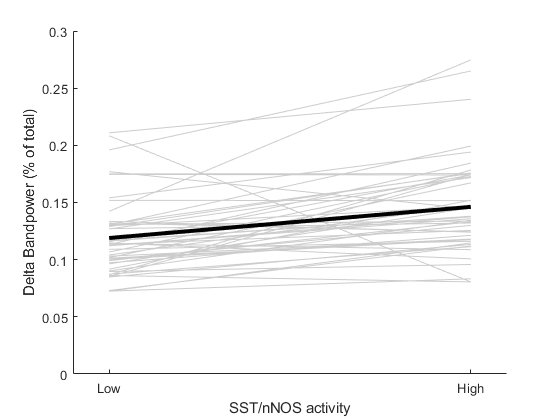

figure
hold on
plot(1:2, [deltaBand.LA deltaBand.HA],'color',[.8 .8 .8])
plot(1:2, [mean(deltaBand.LA, 'omitnan') mean(deltaBand.HA, 'omitnan')], 'k','LineWidth',3)
% errorbar(1:2, [mean(deltaBand.LA, 'omitnan') mean(deltaBand.HA, 'omitnan')], ...
%     [std(deltaBand.LA, 'omitnan') std(deltaBand.HA, 'omitnan')],'k-','LineWidth',2)
xlim([.9 2.1])
ylim([0 max(ylim)])
ylabel('Delta Bandpower (% of total)')
xticks(1:2)
xticklabels({'Low', 'High'})
xlabel('SST/nNOS activity')

figure
hold on
plot(1:2, [ones(size(deltaBand.HA)), deltaBand.HA ./ deltaBand.LA]', 'o-','color',[.8 .8 .8])
plot(1:2, [1 mean(deltaBand.HA./ deltaBand.LA, 'omitnan')]', 'k','LineWidth',3)
errorbar(2, mean(deltaBand.HA ./ deltaBand.LA, 'omitnan'), ...
    std(deltaBand.HA ./ deltaBand.LA, 'omitnan')/sqrt(length(deltaBand.HA)),'k-','LineWidth',2)
xlim([.9 2.1])

% ylim([0 max(ylim)])
plot(xlim,[1 1],'k--')
ylabel('Delta Bandpower (% of total)')
xticks(1:2)
xticklabels({'Low', 'High'})
xlabel('SST/nNOS activity')

disp('t-test on low vs activity delta:')

t-test on low vs activity delta:


[h p] = ttest(deltaBand.HA, deltaBand.LA)

h = 1

p = 9.7184e-06

function output = combineAcrossAnimals(animals)

HASpec = [];
LASpec = [];

for i = 1:length(animals)
    i
    HASpec = [HASpec; animals(i).output.HighActivitySpec];
    LASpec = [LASpec; animals(i).output.LowActivitySpec];
end

freqs = animals(1).output.freqs;

output.HASpec = HASpec;
output.LASpec = LASpec;
output.freqs = freqs;

end

function output = analyzeSpectrum(lfp, imgStruct, specChan, AnimalID, cellIDs)

cellUIDs = string();
for i = 1:length(cellIDs)
    cellUIDs(i) = sprintf('%d_%*d', AnimalID, 2, cellIDs(i));
end

cellType = SSTnNOS.getCellType(cellUIDs);

if ~any(cellType == 1)
    output.HighActivitySpec = nan(1,100);
    output.LowActivitySpec = nan(1,100)
    output.freqs = logspace(log10(1),log10(128),100); % hardcoded from bz_wavespec defaults
    output.QuantileSpec = nan(4,100);
    return
end

% Determining LFP spectrum based on binary of cell activity
normalizedActivityStd = imgStruct.deltaF.data(cellType == 1,:) ./ std(imgStruct.deltaF.data(cellType == 1,:),0,2);
HighActivityInts = booleanToIntervals(mean(normalizedActivityStd,1)' > 2, imgStruct.deltaF.time');
LowActivityInts = booleanToIntervals(mean(normalizedActivityStd,1)' < .5, imgStruct.deltaF.time');

disp('Calculating binary division spectra...')
HASpec = bz_WaveSpec(lfp, 'intervals', HighActivityInts,'downsampleout',2,'ChanID',specChan,'showprogress',true);
LASpec = bz_WaveSpec(lfp, 'intervals', LowActivityInts,'downsampleout',2,'ChanID',specChan,'showprogress',true);

figure
loglog(LASpec.freqs, squeeze(mean(abs(LASpec.data),1,'omitnan')),'k')
hold on
loglog(HASpec.freqs, squeeze(mean(abs(HASpec.data),1,'omitnan')),'k--')
box off
ylabel('Power')
xlabel('Frequency (Hz)')
xticks([1 10 40 100])
legend({'Low Activity Epochs', 'High Activity Epochs'})
title('PSD divided by cell activity')

% Determining LFP spectrum based on quantiles of cell actvitiy
normalizedActivityIQR = (imgStruct.deltaF.data ./ iqr(imgStruct.deltaF.data,2));

nQuantiles = 4;
quantileEdges = [min(mean(normalizedActivityIQR,1)) quantile(mean(normalizedActivityIQR,1),nQuantiles-1) max(mean(normalizedActivityIQR,1))];

[binnedActivity, binTimestamps] = binSignal(mean(normalizedActivityIQR,1), imgStruct.deltaF.time, 3);
quantileEdgesBinned = [min(binnedActivity) quantile(binnedActivity,nQuantiles-1) max(binnedActivity)];
[~, ~, quantileGroup] = histcounts(binnedActivity,quantileEdgesBinned);

quantileInts = cell(1,nQuantiles);
for i = 1:nQuantiles
    quantileInts{i} = ToIntervals(binTimestamps,quantileGroup == i);
end

disp('Calculating quantile division spectra...')
for i = 1:nQuantiles
    quantSpec(i) = bz_WaveSpec(lfp,'intervals', quantileInts{i},'downsampleout',2,'ChanID',specChan,'showprogress',true);
end

figure; hold on;
lineColors = copper(nQuantiles);
for i = 1:nQuantiles
    quantileAS(i,:) = squeeze(mean(abs(quantSpec(i).data),1,'omitnan'));
    plot(quantSpec(i).freqs, squeeze(mean(abs(quantSpec(i).data),1,'omitnan')),'Color',lineColors(i,:),'LineWidth',2)
end
set(gca,'YScale','log')
set(gca,'XScale','log')
ylabel('Power')
xlabel('Frequency (Hz)')
xticks([1 10 40 100])
title('PSD divided by cell activity')
colormap copper
cb = colorbar('eastoutside','ticks',[.05 .95],'TickLabels',{'Low','High'});
ylabel(cb,'Activity Quantile','Position',[2 .5],'Rotation',270)

output.HighActivitySpec = squeeze(mean(abs(HASpec.data),1,'omitnan'));
output.LowActivitySpec = squeeze(mean(abs(LASpec.data),1,'omitnan'));
output.freqs = HASpec.freqs;
output.QuantileSpec = quantileAS(i,:);

end


function ints = booleanToIntervals(booleanSignal, timestamps)

% Check if inputs are column vectors
if ~iscolumn(booleanSignal) || ~iscolumn(timestamps)
    error('Inputs must be column vectors')
end

onsetMask = diff([0; booleanSignal]) == 1;
offsetMask = diff([booleanSignal; 0]) == -1;

ints = [timestamps(onsetMask), timestamps(offsetMask)];
end